# Cart under slow chaotic shaking

 The system is shown pictorially :

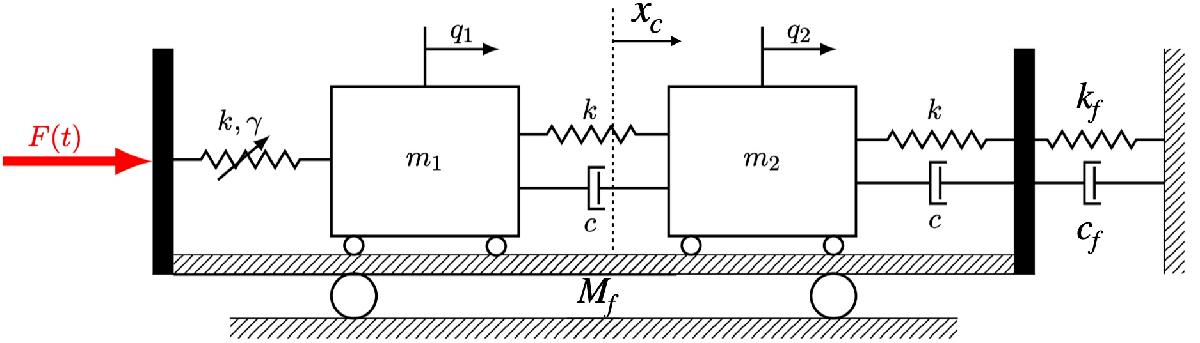

The forcing is easier to express when one moves to the center of mass coordinates and the relative displacement coordinates of the smaller blocks. Further we shift the centre of mass coordinates to make the origin the fixed point. In these coordinates the mechanical system is written as 


$$\mathbf{{M}}=\left(\begin{array}{ccc}
M_{f}\frac{(m_{1}+m_{2})}{M_{T}} & \frac{m_{2}M_{f}}{M_{T}} & 0\\
\frac{m_{2}M_{f}}{M_{T}} & m_{2}\frac{(m_{1}+M_{f})}{M_{T}} & 0\\
0 & 0 & M_{T}
\end{array}\right),\quad{K}=\left(\begin{array}{ccc}
2k+\frac{k_{f}(m_{1}+m_{2})^{2}}{M_{T}^{2}} & k+\frac{k_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & -k_{f}\frac{m_{1}+m_{2}}{M_{T}}\\
k+\frac{k_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & 2k+\frac{k_{f}m_{2}^{2}}{M_{T}^{2}} & -k_{f}\frac{m_{2}}{M_{T}}\\
-k_{f}\frac{m_{1}+m_{2}}{M_{T}} & -k_{f}\frac{m_{2}}{M_{T}} & k_{f}
\end{array}\right),$$


${C}=\left(\begin{array}{ccc}
c+\frac{k_{f}(m_{1}+m_{2})^{2}}{M_{T}^{2}} & c+\frac{c_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & -c_{f}\frac{m_{1}+m_{2}}{M_{T}}\\
c+\frac{c_{f}m_{2}(m_{1}+m_{2})}{M_{T}^{2}} & 2c+\frac{c_{f}m_{2}^{2}}{M_{T}^{2}} & -c_{f}\frac{m_{2}}{M_{T}}\\
-c_{f}\frac{m_{1}+m_{2}}{M_{T}} & -c_{f}\frac{m_{2}}{M_{T}} & c_{f}
\end{array}\right),\quad f(\mathbf{{x},\dot{{x}}})=\left(\begin{array}{c}
\gamma q_{1}^{3}\\
0\\
0
\end{array}\right) \quad \text{{and}\quad}\mathbf{{F}(\alpha = \epsilon t)}=\left(\begin{array}{c}
0\\
0\\
g(\alpha)
\end{array}\right)$.

where $M_{T}=M_{f}+m_{1}+m_{2}$ and ${x}=\left(\begin{array}{c}
q_{1}\\
q_{2}\\
x_{c}
\end{array}\right)$. The autonomous system is got from the Euler-Lagrange equations of the Lagrangian and Rayleigh dissipation function given by


$$L=T+V$$



$$T=\frac{1}{2}M_{f}\dot{x}_{f}^{2}+\frac{1}{2}m_{1}\dot{x}_{1}^{2}+\frac{1}{2}m_{2}\dot{x}_{2}^{2}$$



$$V=\frac{1}{2}kq_{1}^{2}+\frac{1}{2}kq_{2}^{2}+\frac{1}{2}k(L_{2}+L_{1}-3l_{0}-q_{1}-q_{2})^{2}+\frac{1}{4}\gamma q_{1}^{4}+\frac{1}{2}k_{f}(\Lambda-L_{2}-l_{0}-x_{f})^{2}$$



$$R=\frac{1}{2}c\dot{q}_{2}^{2}+\frac{1}{2}c(\dot{q}_{1}+\dot{q}_{2})^{2}+\frac{1}{2}c_{f}\dot{x_{f}}^{2}$$


where $q_{1}=x_{1}-(x_{F}-L_{1})-l_{0}$, $q_{2}=x_{2}-x_{1}-l_{0}$ and $x_{c}=\frac{M_{f}x_{f}+m_{1}x_{1}+m_{2}x_{2}}{M_{f}+m_{1}+m_{2}}-d_{0}$. $L_{1}+L_{2}$ is the length of the cart, $l_{0}$ natural length of the spring and $\Lambda$is the distance of the wall from the user reference frame. Since we assume the block masses are point masses we have $L_{1}+L_{2}=3l_{0}$. The length $d_{0}$ represents the equilibrium position of the centre of mass from the user reference frame, subtracting this from the centre of mass gives the shifted coordinate $x_{c}$. From the free body diagram of the cart the forcing acts on the centre of mass coordinate of the cart, hence appears as a collective shaking force that influences all the degrees of the freedom of the cart.

The signal $g(\alpha)$ is generated using the initial condition $[0.8;0.3;0.2]$ and is scaled by a factor of 10. The system paramters and forcing are generated below: 

clear all
m1 = 1;
m2 = 1;
Mf = 2;
kf = 1;
k = 1;
c = 0.3;
cf = 0.3;
gamma = 0.5;
MTT = m1 + m2 + Mf;
K = -[-2*k - kf*((m1 + m2)/MTT)^2, -k - kf*m2*(m1 + m2)/MTT^2, kf*(m1+m2)/MTT; -k - kf*m2*(m1 + m2)/MTT^2, -2*k - kf*m2^2/(MTT^2), kf*m2/MTT; (m1 + m2)/MTT *kf, m2/MTT*kf, -kf];
C = -[-c - cf*((m1 + m2)/MTT)^2, -c - cf*m2*(m1 + m2)/MTT^2, cf*(m1+m2)/MTT; -c - cf*m2*(m1 + m2)/MTT^2, -2*c - cf*m2^2/(MTT^2), cf*m2/MTT; (m1 + m2)/MTT *cf, m2/MTT*cf, -cf];
M =  [Mf*(m1 + m2)/MTT, m2*Mf/MTT, 0; m2*Mf/MTT, m2*(m1 + Mf)/MTT, 0; 0,0, MTT];

A = [zeros(3),eye(3);inv(M)*K,inv(M)*C];
% w1 = sqrt(k/m);
% w2 = sqrt(3*k/m);
% ls = (-c/(2*m*w1) + 1i*sqrt(1-c^2/(4*m^2*w1^2)))*sqrt(k/m);
% lf = (-(3*c)/(2*m*w2) + 1i*sqrt(1-(3*c)^2/(4*m^2*w2^2)))*sqrt(3*k/m);

subs2 = [1 1 1 1];
n = 3;
F3 = sptensor(subs2, gamma, [n,n,n,n]);
F2 = sptensor([n,n,n]);
fnl = {F2,F3};


n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 3


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 6


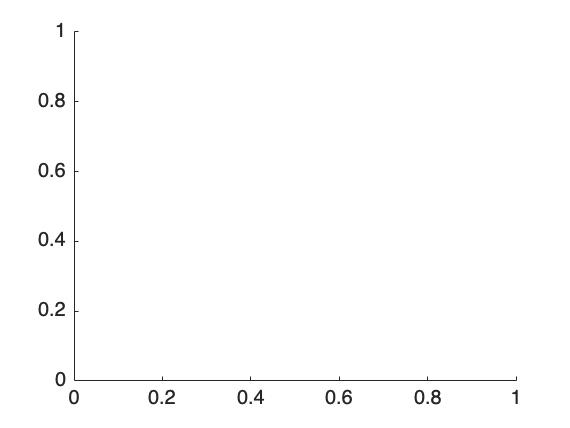



%%
% DS set up - SSM tool
hold on

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',6,'Nmax',10,'notation','multiindex')
[V,D,W] = DS.linear_spectral_analysis();


 The first 6 nonzero eigenvalues are given as 
  -0.0307 + 0.4674i
  -0.0307 - 0.4674i
  -0.1703 + 1.5308i
  -0.1703 - 1.5308i
  -0.3991 + 1.6499i
  -0.3991 - 1.6499i



S = SSM(DS);
resonant_modes = [1 2];
Acheck = V*diag(D)*inv(V);
VI = inv(V);

tic
[F, lambda, V, G, DG] = functionFromTensors(M, C, K, fnl);
toc

Elapsed time is 2.605309 seconds.




%Lorenz force 
%%

L = -15;
N_Max = 10000;
tspan = linspace(L,20,N_Max);
loren = @(t,y) lorenz_3D(t,y);
IC = [0.8;0.3;0.2];
[tk,yy] = ode45(loren,tspan,IC);

sigma = 10;
rho = 28;
beta = 8/3;

% F_a = -(sigma*rho*yy(:,1) - sigma*yy(:,1).*yy(:,3) - sigma*yy(:,2) - sigma^2*yy(:,2) + sigma^2*yy(:,1));
scaling = 10;
F_a_new = scaling*yy(:,1)/max(abs(yy(:,1)));


Force_Lorenz = griddedInterpolant(tspan(:),F_a_new(:),'spline');

% Force_Lorenz = @(alpha) scaling*sin(alpha);
% F_a_new = Force_Lorenz(tk);

fig1 = figure

fig1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


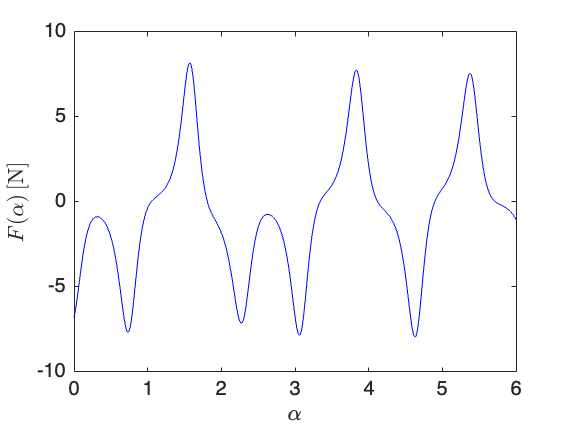

plot(tk,F_a_new,'Color','blue')
xlabel('$\alpha$','Interpreter','latex');
ylabel('$F(\alpha) \,[$N$]$','Interpreter','latex');
axis([0 6 -10 10])

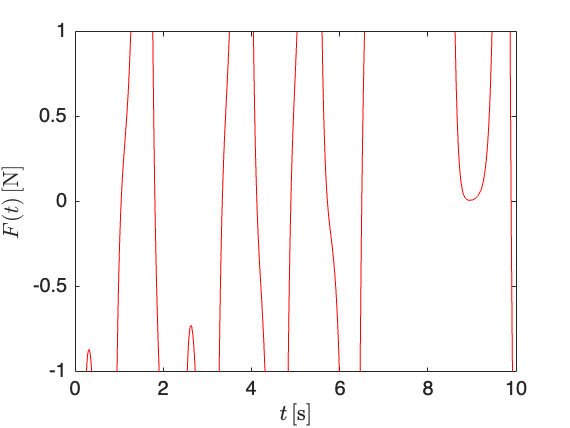


% set(fig1, 'Units' , 'Inches' );
% pos = get(fig1, 'Position' );
% set(fig1, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig1, 'forcing_slow.pdf' , '-dpdf' , '-r300' )


pos_t = find(tk>=0);
figure
plot(tk(pos_t),F_a_new(pos_t),'Color','red')
xlabel('$t \,[$s$]$','Interpreter','latex');
ylabel('$F(t) \,[$N$]$','Interpreter','latex');
axis([0 10 -1 1])

The anchor trajectory is calculated to O(3). The non-zero anchor trajectory at various orders are saved. If you wish to recompute these please set flag to 1. 

flag1 =0;
flag =0;
if flag1 == 1

[Vcheck,Dcheck] = eig(full(Acheck));
V0 = Vcheck;
 N_grid = 1000;
Grid_F = linspace(-max(F_a_new),max(F_a_new),N_grid);
VT = cell(1,N_grid);
DT = cell(1,N_grid);
ICTT = cell(1,N_grid);
AT = cell(1,N_grid);
for i = 1:N_grid
load_vector = [0;0;Grid_F(i)];
IC = getStaticResponse(K, M, F, load_vector, 0, 0);
ICTT{1,i} = IC(1:n,1);
[K_shift,fnl_shift] = build_model_shift(K,fnl,IC(1:n,1));
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K_shift,'fnl',fnl_shift);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
[V,D,W] = DS.linear_spectral_analysis();
AT{1,i} = DS.BinvA;

DT{1,i} = D;


[Vcheck,Dcheck] = eig(full(AT{1,i}));
dsa = diag(Dcheck);
[d,ind]=sort(real(-dsa));
Ds=Dcheck(ind,ind);         %sorted eigenvalue matrix
Vs=Vcheck(:,ind); 

VC = reorient_complex(Vs,V0);
VT{1,i} = VC;


end    

 save('VSP.mat','VT','V','Grid_F');
 save('ASP.mat','AT','A','Grid_F');
 save('DSP.mat','DT','Grid_F');
 save('ICSP.mat','ICTT','Grid_F');
end


 load('VSP.mat','VT','V','Grid_F');
 load('ASP.mat','AT','A','Grid_F');
 load('DSP.mat','DT','Grid_F');
 load('ICSP.mat','ICTT','Grid_F');


VarA = [];
AarA = [];
DarA = [];
IarA = [];
for ind = 1:max(size(Grid_F))
VarA = [VarA,VT{1,ind}(:)];
AarA = [AarA,full(AT{1,ind}(:))];
DarA = [DarA,DT{1,ind}(:)];
IarA = [IarA,ICTT{1,ind}(:)];
end    

ValphaR = griddedInterpolant(Grid_F(:),real(VarA).','spline');
ValphaI = griddedInterpolant(Grid_F(:),imag(VarA).','spline');
Valpha = @(F,V) reshape((ValphaR(F) + 1i*ValphaI(F)).',max(size(V(:,1))),max(size(V(1,:))));

Aalpha = griddedInterpolant(Grid_F(:),AarA.','spline');
Aalph = @(F,A) reshape(Aalpha(F).',max(size(A(:,1))),max(size(A(1,:))));

Dalpha = griddedInterpolant(Grid_F(:),DarA.','spline');
Dalph = @(F) Dalpha(F);

Ialpha = griddedInterpolant(Grid_F(:),IarA.','spline');
Ialph = @(F) Ialpha(F);
epsilon = 0.008;

if flag ==1
%Order 0
xi_0 = @(alpha) [Ialpha(Force_Lorenz(alpha)).';0;0;0];

% Order 1

Load_Check = Ialph(F_a_new).';
[dXdF, Xtrunc,tkr1] = ftd(Load_Check, tk.');
IDalpha = griddedInterpolant(tkr1(:),dXdF.','spline');

ParA = [];
for gen_f = 1:max(size(F_a_new))
    P = Valpha(F_a_new(gen_f),V);
    ParA = [ParA,P(:)];
end    
[dXdFr, Xtruncr,tkr1] = ftd(real(ParA), tk.');
[dXdFi, Xtrunci,tkr1] = ftd(imag(ParA), tk.');
VDalphaR = griddedInterpolant(tkr1(:),dXdFr.','spline');
VDalphaI = griddedInterpolant(tkr1(:),dXdFi.','spline');
ValphaD = @(F,V) reshape((VDalphaR(F) + 1i*VDalphaI(F)).',max(size(V(:,1))),max(size(V(1,:))));

% [dXdFPa, XtruncPa,F_truncPa] = ftd(F_a_new.', tk.');
%  
% DForce_Lorenz = griddedInterpolant(F_truncPa(:),dXdFPa(:),'spline');

xi_1 = @(alpha,A) (inv(Aalph(Force_Lorenz(alpha),A))*[IDalpha(alpha).';0;0;0]);
XI_1 = [];
for indf = 1:max(size(tkr1))
    vec1=xi_1(tkr1(indf),A);
    XI_1 = [XI_1,vec1];
end    
% Order 2 

[dXdF, Xtrunc,tkr2] = ftd(XI_1, tkr1);
xi_1D = griddedInterpolant(tkr2(:),dXdF.','spline');
wrap = @(a,x)a(x);
xi_11 = @(alpha,A) wrap(xi_1(alpha,A),1);
xi_01 = @(alpha) wrap(xi_0(alpha),1);

xi_2 = @(alpha,A) (inv(Aalph(Force_Lorenz(alpha),A))*(xi_1D(alpha).'-[0;0;0;-3*gamma*(m1+Mf)/(m1*Mf)*xi_01(alpha)*xi_11(alpha,A)^2;3*gamma/m1*xi_01(alpha)*xi_11(alpha,A)^2;0]));

XI_2 = [];
for indf = 1:max(size(tkr2))
    vec1=xi_2(tkr2(indf),A);
    XI_2 = [XI_2,vec1];
end 

% Order 3
[dXdF, Xtrunc,tkr3] = ftd(XI_2, tkr2);
xi_2D = griddedInterpolant(tkr3(:),dXdF.','spline');
xi_21 = @(alpha,A) wrap(xi_2(alpha,A),1);

xi_3 = @(alpha,A) (inv(Aalph(Force_Lorenz(alpha),A))*(xi_2D(alpha).'-[0;0;0;-gamma*(m1+Mf)/(m1*Mf)*(xi_11(alpha,A)^3+6*xi_01(alpha)*xi_11(alpha,A)*xi_21(alpha,A));gamma/m1*(xi_11(alpha,A)^3+6*xi_01(alpha)*xi_11(alpha,A)*xi_21(alpha,A));0]));

XI_3A = [];
check_2D = [];
for indf = 1:max(size(tkr3))
    vec1=xi_3(tkr3(indf),A);
    check_2D = [check_2D,xi_1D(tkr3(indf)).'];
    XI_3A = [XI_3A,vec1];
end 

XI_2A = [];
for indf = 1:max(size(tkr3))
    vec1=xi_2(tkr3(indf),A);
    XI_2A = [XI_2A,vec1];
end 

XI_1A = [];
for indf = 1:max(size(tkr3))
    vec1=xi_1(tkr3(indf),A);
    XI_1A = [XI_1A,vec1];
end 

XI_0A = [];
for indf = 1:max(size(tkr3))
    vec1=xi_0(tkr3(indf));
    XI_0A = [XI_0A,vec1];
end 

%
XI_0 = griddedInterpolant(tkr3(:),XI_0A.','spline');
XI_1 = griddedInterpolant(tkr3(:),XI_1A.','spline');
XI_2 = griddedInterpolant(tkr3(:),XI_2A.','spline');

porder = 5;
framelen = 101;
sgf1 = sgolayfilt(XI_3A(1,:),porder,framelen);
sgf2 = sgolayfilt(XI_3A(2,:),porder,framelen);
sgf3 = sgolayfilt(XI_3A(3,:),porder,framelen);
sgf4 = sgolayfilt(XI_3A(4,:),porder,framelen);
sgf5 = sgolayfilt(XI_3A(5,:),porder,framelen);
sgf6 = sgolayfilt(XI_3A(6,:),porder,framelen);
XI_3f = [sgf1;sgf2;sgf3;sgf4;sgf5;sgf6];

XI_3 = griddedInterpolant(tkr3(:),XI_3f.','spline');
save('Solution.mat','XI_0','XI_1','XI_2','XI_3','tkr3','tkr2','tkr1','xi_01','xi_11','xi_21','ValphaD','wrap');

end 
load('Solution.mat','XI_0','XI_1','XI_2','XI_3','tkr3','tkr2','tkr1','xi_01','xi_11','xi_21','ValphaD','wrap');

Now we calculate the non-autonomous SSM coefficients upto this order by solving the invariance PDE. 

if flag == 1
Coeff_Iterate_1 = [];
for indf = 1:max(size(tkr2))
dia = Dalpha(Force_Lorenz(tkr2(indf)));
l1 = dia(1);
l1c = conj(l1);
l2 = dia(3);
l3 = dia(5);
alpha = tkr2(indf);
xi0 = xi_01(alpha);
xi1 = xi_11(alpha,A);
P = Valpha(Force_Lorenz(tkr2(indf)),V);
PI = inv(P);
PD = ValphaD(alpha,V);

h101 = (-(m1.*Mf.*PD(1, 1).*PI(3, 1)) - m1.*Mf.*PD(2, 1).*PI(3, 2) - m1.*Mf.*PD(3, 1).*PI(3, 3) - 6.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(3, 4) - 6.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(3, 4) - ...
     m1.*Mf.*PD(4, 1).*PI(3, 4) + 6.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(3, 5) - m1.*Mf.*PD(5, 1).*PI(3, 5) - m1.*Mf.*PD(6, 1).*PI(3, 6))./((l1 - l2).*m1.*Mf);
hc011 = conj(h101);

h200 = (-3.*(gamma.*m1.*xi0.*P(1, 1).^2.*PI(3, 4) + gamma.*Mf.*xi0.*P(1, 1).^2.*PI(3, 4) - gamma.*Mf.*xi0.*P(1, 1).^2.*PI(3, 5)))./((2.*l1 - l2).*m1.*Mf);
hc020 = conj(h200);

h011 = (-(m1.*Mf.*PD(1, 2).*PI(3, 1)) - m1.*Mf.*PD(2, 2).*PI(3, 2) - m1.*Mf.*PD(3, 2).*PI(3, 3) - 6.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(3, 4) - 6.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(3, 4) - ...
     m1.*Mf.*PD(4, 2).*PI(3, 4) + 6.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(3, 5) - m1.*Mf.*PD(5, 2).*PI(3, 5) - m1.*Mf.*PD(6, 2).*PI(3, 6))./((l1c - l2).*m1.*Mf);
hc101 = conj(h011);

h110 = (-6.*(gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(3, 4) + gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(3, 4) - gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(3, 5)))./((l1+l1c - l2).*m1.*Mf);
hc110 = conj(h110);

h020 = (-3.*(gamma.*m1.*xi0.*P(1, 2).^2.*PI(3, 4) + gamma.*Mf.*xi0.*P(1, 2).^2.*PI(3, 4) - gamma.*Mf.*xi0.*P(1, 2).^2.*PI(3, 5)))./((2.*l1c - l2).*m1.*Mf);
hc200 = conj(h020);

f101 = (-(m1.*Mf.*PD(1, 1).*PI(5, 1)) - m1.*Mf.*PD(2, 1).*PI(5, 2) - m1.*Mf.*PD(3, 1).*PI(5, 3) - 6.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(5, 4) - 6.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(5, 4) - ...
     m1.*Mf.*PD(4, 1).*PI(5, 4) + 6.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(5, 5) - m1.*Mf.*PD(5, 1).*PI(5, 5) - m1.*Mf.*PD(6, 1).*PI(5, 6))./((l1 - l3).*m1.*Mf);
fc011 = conj(f101);

f200 = (-3.*(gamma.*m1.*xi0.*P(1, 1).^2.*PI(5, 4) + gamma.*Mf.*xi0.*P(1, 1).^2.*PI(5, 4) - gamma.*Mf.*xi0.*P(1, 1).^2.*PI(5, 5)))./((2.*l1 - l3).*m1.*Mf);
fc020 = conj(f200);

f011 = (-(m1.*Mf.*PD(1, 2).*PI(5, 1)) - m1.*Mf.*PD(2, 2).*PI(5, 2) - m1.*Mf.*PD(3, 2).*PI(5, 3) - 6.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(5, 4) - 6.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(5, 4) - ...
     m1.*Mf.*PD(4, 2).*PI(5, 4) + 6.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(5, 5) - m1.*Mf.*PD(5, 2).*PI(5, 5) - m1.*Mf.*PD(6, 2).*PI(5, 6))./((l1c - l3).*m1.*Mf);
fc101 = conj(f011);

f110 = (-6.*(gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(5, 4) + gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(5, 4) - gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(5, 5)))./((l1+l1c - l3).*m1.*Mf);
fc110 = conj(f110);

f020 = (-3.*(gamma.*m1.*xi0.*P(1, 2).^2.*PI(5, 4) + gamma.*Mf.*xi0.*P(1, 2).^2.*PI(5, 4) - gamma.*Mf.*xi0.*P(1, 2).^2.*PI(5, 5)))./((2.*l1c - l3).*m1.*Mf);
fc200 = conj(f020);

h300 = (6.*gamma.*h200.*m1.*xi0.*P(1, 1).^2.*PI(1, 4) + 6.*gamma.*h200.*Mf.*xi0.*P(1, 1).^2.*PI(1, 4) - 6.*gamma.*h200.*Mf.*xi0.*P(1, 1).^2.*PI(1, 5) + 3.*gamma.*h110.*m1.*xi0.*P(1, 1).^2.*PI(2, 4) + ...
     3.*gamma.*h110.*Mf.*xi0.*P(1, 1).^2.*PI(2, 4) - 3.*gamma.*h110.*Mf.*xi0.*P(1, 1).^2.*PI(2, 5) - gamma.*m1.*P(1, 1).^3.*PI(3, 4) - gamma.*Mf.*P(1, 1).^3.*PI(3, 4) - ...
     6.*gamma.*h200.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 6.*gamma.*h200.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 6.*gamma.*hc200.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - ...
     6.*gamma.*hc200.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 6.*f200.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 6.*f200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - ...
     6.*fc200.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - 6.*fc200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) + gamma.*Mf.*P(1, 1).^3.*PI(3, 5) + 6.*gamma.*h200.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 5) + ...
     6.*gamma.*hc200.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 5) + 6.*f200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 5) + 6.*fc200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 5))./((3.*l1 - l2).*m1.*Mf);

h030 = (3.*gamma.*h110.*m1.*xi0.*P(1, 2).^2.*PI(1, 4) + 3.*gamma.*h110.*Mf.*xi0.*P(1, 2).^2.*PI(1, 4) - 3.*gamma.*h110.*Mf.*xi0.*P(1, 2).^2.*PI(1, 5) + 6.*gamma.*h020.*m1.*xi0.*P(1, 2).^2.*PI(2, 4) + ...
     6.*gamma.*h020.*Mf.*xi0.*P(1, 2).^2.*PI(2, 4) - 6.*gamma.*h020.*Mf.*xi0.*P(1, 2).^2.*PI(2, 5) - gamma.*m1.*P(1, 2).^3.*PI(3, 4) - gamma.*Mf.*P(1, 2).^3.*PI(3, 4) - ...
     6.*gamma.*h020.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 6.*gamma.*h020.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 6.*gamma.*hc020.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - ...
     6.*gamma.*hc020.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 6.*f020.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - 6.*f020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - ...
     6.*fc020.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - 6.*fc020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) + gamma.*Mf.*P(1, 2).^3.*PI(3, 5) + 6.*gamma.*h020.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 5) + ...
     6.*gamma.*hc020.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 5) + 6.*f020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 5) + 6.*fc020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 5))./((3.*l1c - l2).*m1.*Mf);

h120 = (3.*(2.*gamma.*h110.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + 2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + 2.*gamma.*h200.*m1.*xi0.*P(1, 2).^2.*PI(1, 4) + ...
      2.*gamma.*h200.*Mf.*xi0.*P(1, 2).^2.*PI(1, 4) - 2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 5) - 2.*gamma.*h200.*Mf.*xi0.*P(1, 2).^2.*PI(1, 5) + ...
      4.*gamma.*h020.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + 4.*gamma.*h020.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + gamma.*h110.*m1.*xi0.*P(1, 2).^2.*PI(2, 4) + gamma.*h110.*Mf.*xi0.*P(1, 2).^2.*PI(2, 4) - ...
      4.*gamma.*h020.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 5) - gamma.*h110.*Mf.*xi0.*P(1, 2).^2.*PI(2, 5) - gamma.*m1.*P(1, 1).*P(1, 2).^2.*PI(3, 4) - gamma.*Mf.*P(1, 1).*P(1, 2).^2.*PI(3, 4) - ...
      2.*gamma.*h020.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 2.*gamma.*h020.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 2.*gamma.*h110.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 2.*gamma.*hc020.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 2.*gamma.*hc020.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - ...
      2.*gamma.*hc110.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 2.*gamma.*hc110.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 2.*f020.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - ...
      2.*f020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 2.*f110.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - 2.*f110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - ...
      2.*fc020.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - 2.*fc020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - 2.*fc110.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - ...
      2.*fc110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) + gamma.*Mf.*P(1, 1).*P(1, 2).^2.*PI(3, 5) + 2.*gamma.*h020.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 5) + ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 5) + 2.*gamma.*hc020.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 5) + 2.*gamma.*hc110.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 5) + ...
      2.*f020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 5) + 2.*f110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 5) + 2.*fc020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 5) + ...
      2.*fc110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 5)))./((l1+2.*l1c - l2).*m1.*Mf);

h210 = (3.*(gamma.*h110.*m1.*xi0.*P(1, 1).^2.*PI(1, 4) + gamma.*h110.*Mf.*xi0.*P(1, 1).^2.*PI(1, 4) + 4.*gamma.*h200.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + ...
      4.*gamma.*h200.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) - gamma.*h110.*Mf.*xi0.*P(1, 1).^2.*PI(1, 5) - 4.*gamma.*h200.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 5) + ...
      2.*gamma.*h020.*m1.*xi0.*P(1, 1).^2.*PI(2, 4) + 2.*gamma.*h020.*Mf.*xi0.*P(1, 1).^2.*PI(2, 4) + 2.*gamma.*h110.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) - 2.*gamma.*h020.*Mf.*xi0.*P(1, 1).^2.*PI(2, 5) - 2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 5) - gamma.*m1.*P(1, 1).^2.*P(1, 2).*PI(3, 4) - ...
      gamma.*Mf.*P(1, 1).^2.*P(1, 2).*PI(3, 4) - 2.*gamma.*h110.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - ...
      2.*gamma.*h200.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 2.*gamma.*h200.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 2.*gamma.*hc110.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - ...
      2.*gamma.*hc110.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 2.*gamma.*hc200.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 2.*gamma.*hc200.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - ...
      2.*f110.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 2.*f200.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - ...
      2.*f200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - 2.*fc110.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - 2.*fc110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - ...
      2.*fc200.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - 2.*fc200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) + gamma.*Mf.*P(1, 1).^2.*P(1, 2).*PI(3, 5) + ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 5) + 2.*gamma.*h200.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 5) + 2.*gamma.*hc110.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 5) + ...
      2.*gamma.*hc200.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 5) + 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 5) + 2.*f200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 5) + ...
      2.*fc110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 5) + 2.*fc200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 5)))./((2.*l1+l1c - l2).*m1.*Mf);


f300 = (6.*f200.*gamma.*m1.*xi0.*P(1, 1).^2.*PI(1, 4) + 6.*f200.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(1, 4) - 6.*f200.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(1, 5) + 3.*f110.*gamma.*m1.*xi0.*P(1, 1).^2.*PI(2, 4) + ...
     3.*f110.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(2, 4) - 3.*f110.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(2, 5) - gamma.*m1.*P(1, 1).^3.*PI(5, 4) - gamma.*Mf.*P(1, 1).^3.*PI(5, 4) - ...
     6.*gamma.*h200.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 6.*gamma.*h200.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 6.*gamma.*hc200.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - ...
     6.*gamma.*hc200.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 6.*f200.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 6.*f200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - ...
     6.*fc200.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - 6.*fc200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) + gamma.*Mf.*P(1, 1).^3.*PI(5, 5) + 6.*gamma.*h200.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 5) + ...
     6.*gamma.*hc200.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 5) + 6.*f200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 5) + 6.*fc200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 5))./((3.*l1 - l3).*m1.*Mf);

f030 = (3.*f110.*gamma.*m1.*xi0.*P(1, 2).^2.*PI(1, 4) + 3.*f110.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(1, 4) - 3.*f110.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(1, 5) + 6.*f020.*gamma.*m1.*xi0.*P(1, 2).^2.*PI(2, 4) + ...
     6.*f020.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(2, 4) - 6.*f020.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(2, 5) - gamma.*m1.*P(1, 2).^3.*PI(5, 4) - gamma.*Mf.*P(1, 2).^3.*PI(5, 4) - ...
     6.*gamma.*h020.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 6.*gamma.*h020.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 6.*gamma.*hc020.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - ...
     6.*gamma.*hc020.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 6.*f020.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - 6.*f020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - ...
     6.*fc020.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - 6.*fc020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) + gamma.*Mf.*P(1, 2).^3.*PI(5, 5) + 6.*gamma.*h020.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 5) + ...
     6.*gamma.*hc020.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 5) + 6.*f020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 5) + 6.*fc020.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 5))./((3.*l1c - l3).*m1.*Mf);

f120 = (3.*(2.*f110.*gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + 2.*f200.*gamma.*m1.*xi0.*P(1, 2).^2.*PI(1, 4) + ...
      2.*f200.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(1, 4) - 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 5) - 2.*f200.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(1, 5) + ...
      4.*f020.*gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + 4.*f020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + f110.*gamma.*m1.*xi0.*P(1, 2).^2.*PI(2, 4) + f110.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(2, 4) - ...
      4.*f020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 5) - f110.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(2, 5) - gamma.*m1.*P(1, 1).*P(1, 2).^2.*PI(5, 4) - gamma.*Mf.*P(1, 1).*P(1, 2).^2.*PI(5, 4) - ...
      2.*gamma.*h020.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 2.*gamma.*h020.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 2.*gamma.*h110.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 2.*gamma.*hc020.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 2.*gamma.*hc020.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - ...
      2.*gamma.*hc110.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 2.*gamma.*hc110.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 2.*f020.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - ...
      2.*f020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 2.*f110.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - 2.*f110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - ...
      2.*fc020.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - 2.*fc020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - 2.*fc110.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - ...
      2.*fc110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) + gamma.*Mf.*P(1, 1).*P(1, 2).^2.*PI(5, 5) + 2.*gamma.*h020.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 5) + ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 5) + 2.*gamma.*hc020.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 5) + 2.*gamma.*hc110.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 5) + ...
      2.*f020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 5) + 2.*f110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 5) + 2.*fc020.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 5) + ...
      2.*fc110.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 5)))./((l1+2.*l1c - l3).*m1.*Mf);


f210 = (3.*(f110.*gamma.*m1.*xi0.*P(1, 1).^2.*PI(1, 4) + f110.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(1, 4) + 4.*f200.*gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + ...
      4.*f200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) - f110.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(1, 5) - 4.*f200.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 5) + ...
      2.*f020.*gamma.*m1.*xi0.*P(1, 1).^2.*PI(2, 4) + 2.*f020.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(2, 4) + 2.*f110.*gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + ...
      2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) - 2.*f020.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(2, 5) - 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 5) - gamma.*m1.*P(1, 1).^2.*P(1, 2).*PI(5, 4) - ...
      gamma.*Mf.*P(1, 1).^2.*P(1, 2).*PI(5, 4) - 2.*gamma.*h110.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - ...
      2.*gamma.*h200.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 2.*gamma.*h200.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 2.*gamma.*hc110.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - ...
      2.*gamma.*hc110.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 2.*gamma.*hc200.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 2.*gamma.*hc200.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - ...
      2.*f110.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 2.*f200.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - ...
      2.*f200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - 2.*fc110.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - 2.*fc110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - ...
      2.*fc200.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - 2.*fc200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) + gamma.*Mf.*P(1, 1).^2.*P(1, 2).*PI(5, 5) + ...
      2.*gamma.*h110.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 5) + 2.*gamma.*h200.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 5) + 2.*gamma.*hc110.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 5) + ...
      2.*gamma.*hc200.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 5) + 2.*f110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 5) + 2.*f200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 5) + ...
      2.*fc110.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 5) + 2.*fc200.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 5)))./((2.*l1+l1c - l3).*m1.*Mf);




vecC = [h101;h200;h011;h110;h020;f101;f200;f011;f110;f020;h300;h030;h120;h210;f300;f030;f120;f210];

Coeff_Iterate_1 = [Coeff_Iterate_1,vecC];

end
SSM_Coeff_A_1 = griddedInterpolant(tkr2(:),Coeff_Iterate_1.','spline');

[dXdF, Xtrunc,tkr3] = ftd(Coeff_Iterate_1, tkr2);
DSSM_Coeff_A_1 = griddedInterpolant(tkr3(:),dXdF.','spline');

save('Adiabatic_SSM_coeff.mat','SSM_Coeff_A_1')
save('Adiabatic_SSM_coeffD.mat','DSSM_Coeff_A_1')
% 
Coeff_Iterate_2 = [];
for indf = 1:max(size(tkr3))

    dia = Dalpha(Force_Lorenz(tkr3(indf)));
    l1 = dia(1);
    l1c = conj(l1);
    l2 = dia(3);
    l3 = dia(5);
    alpha = tkr3(indf);
    xi0 = xi_01(alpha);
    xi1 = xi_11(alpha,A);
    xi2 = xi_21(alpha,A);
    P = Valpha(Force_Lorenz(tkr3(indf)),V);
    PI = inv(P);
    PD = ValphaD(alpha,V);
    TempCell = num2cell(SSM_Coeff_A_1(alpha));
    [h101,h200,h011,h110,h020,f101,f200,f011,f110,f020,h300,h030,h120,h210,f300,f030,f120,f210]=deal(TempCell{:});
    TempCell = num2cell(DSSM_Coeff_A_1(alpha));
    [hd101,hd200,hd011,hd110,hd020,fd101,fd200,fd011,fd110,fd020,hd300,hd030,hd120,hd210,fd300,fd030,fd120,fd210]=deal(TempCell{:});
    TempCell = num2cell(conj([h101,h200,h011,h110,h020,f101,f200,f011,f110,f020,h300,h030,h120,h210,f300,f030,f120,f210]));
    [hc011,hc020,hc101,hc110,hc200,fc011,fc020,fc101,fc110,fc200,hc030,hc300,hc210,hc120,fc030,fc300,fc210,fc120] = deal(TempCell{:});


h012 = (-(hd011.*m1.*Mf) + h101.*m1.*Mf.*PD(1, 2).*PI(1, 1) + h101.*m1.*Mf.*PD(2, 2).*PI(1, 2) + h101.*m1.*Mf.*PD(3, 2).*PI(1, 3) + 6.*gamma.*h101.*m1.*xi0.*xi1.*P(1, 2).*PI(1, 4) + ...
     6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 4) + h101.*m1.*Mf.*PD(4, 2).*PI(1, 4) - 6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 5) + h101.*m1.*Mf.*PD(5, 2).*PI(1, 5) + ...
     h101.*m1.*Mf.*PD(6, 2).*PI(1, 6) + h011.*m1.*Mf.*PD(1, 2).*PI(2, 1) + h011.*m1.*Mf.*PD(2, 2).*PI(2, 2) + h011.*m1.*Mf.*PD(3, 2).*PI(2, 3) + 6.*gamma.*h011.*m1.*xi0.*xi1.*P(1, 2).*PI(2, 4) + ...
     6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 4) + h011.*m1.*Mf.*PD(4, 2).*PI(2, 4) - 6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 5) + h011.*m1.*Mf.*PD(5, 2).*PI(2, 5) + ...
     h011.*m1.*Mf.*PD(6, 2).*PI(2, 6) - h011.*m1.*Mf.*PD(1, 3).*PI(3, 1) - hc011.*m1.*Mf.*PD(1, 4).*PI(3, 1) - f011.*m1.*Mf.*PD(1, 5).*PI(3, 1) - fc011.*m1.*Mf.*PD(1, 6).*PI(3, 1) - ...
     h011.*m1.*Mf.*PD(2, 3).*PI(3, 2) - hc011.*m1.*Mf.*PD(2, 4).*PI(3, 2) - f011.*m1.*Mf.*PD(2, 5).*PI(3, 2) - fc011.*m1.*Mf.*PD(2, 6).*PI(3, 2) - h011.*m1.*Mf.*PD(3, 3).*PI(3, 3) - ...
     hc011.*m1.*Mf.*PD(3, 4).*PI(3, 3) - f011.*m1.*Mf.*PD(3, 5).*PI(3, 3) - fc011.*m1.*Mf.*PD(3, 6).*PI(3, 3) - 3.*gamma.*m1.*xi1.^2.*P(1, 2).*PI(3, 4) - 3.*gamma.*Mf.*xi1.^2.*P(1, 2).*PI(3, 4) - ...
     6.*gamma.*m1.*xi0.*xi2.*P(1, 2).*PI(3, 4) - 6.*gamma.*Mf.*xi0.*xi2.*P(1, 2).*PI(3, 4) - 6.*gamma.*h011.*m1.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 4) - ...
     6.*gamma.*hc011.*m1.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*gamma.*hc011.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*f011.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(3, 4) - 6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 4) - ...
     6.*fc011.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc011.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 4) - h011.*m1.*Mf.*PD(4, 3).*PI(3, 4) - hc011.*m1.*Mf.*PD(4, 4).*PI(3, 4) - ...
     f011.*m1.*Mf.*PD(4, 5).*PI(3, 4) - fc011.*m1.*Mf.*PD(4, 6).*PI(3, 4) + 3.*gamma.*Mf.*xi1.^2.*P(1, 2).*PI(3, 5) + 6.*gamma.*Mf.*xi0.*xi2.*P(1, 2).*PI(3, 5) + ...
     6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 5) + 6.*gamma.*hc011.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 5) + 6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 5) + 6.*fc011.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 5) - ...
     h011.*m1.*Mf.*PD(5, 3).*PI(3, 5) - hc011.*m1.*Mf.*PD(5, 4).*PI(3, 5) - f011.*m1.*Mf.*PD(5, 5).*PI(3, 5) - fc011.*m1.*Mf.*PD(5, 6).*PI(3, 5) - h011.*m1.*Mf.*PD(6, 3).*PI(3, 6) - ...
     hc011.*m1.*Mf.*PD(6, 4).*PI(3, 6) - f011.*m1.*Mf.*PD(6, 5).*PI(3, 6) - fc011.*m1.*Mf.*PD(6, 6).*PI(3, 6))./((l1c - l2).*m1.*Mf);

h102 = (-(hd101.*m1.*Mf) + h101.*m1.*Mf.*PD(1, 1).*PI(1, 1) + h101.*m1.*Mf.*PD(2, 1).*PI(1, 2) + h101.*m1.*Mf.*PD(3, 1).*PI(1, 3) + 6.*gamma.*h101.*m1.*xi0.*xi1.*P(1, 1).*PI(1, 4) + ...
     6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 4) + h101.*m1.*Mf.*PD(4, 1).*PI(1, 4) - 6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 5) + h101.*m1.*Mf.*PD(5, 1).*PI(1, 5) + ...
     h101.*m1.*Mf.*PD(6, 1).*PI(1, 6) + h011.*m1.*Mf.*PD(1, 1).*PI(2, 1) + h011.*m1.*Mf.*PD(2, 1).*PI(2, 2) + h011.*m1.*Mf.*PD(3, 1).*PI(2, 3) + 6.*gamma.*h011.*m1.*xi0.*xi1.*P(1, 1).*PI(2, 4) + ...
     6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 4) + h011.*m1.*Mf.*PD(4, 1).*PI(2, 4) - 6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 5) + h011.*m1.*Mf.*PD(5, 1).*PI(2, 5) + ...
     h011.*m1.*Mf.*PD(6, 1).*PI(2, 6) - h101.*m1.*Mf.*PD(1, 3).*PI(3, 1) - hc101.*m1.*Mf.*PD(1, 4).*PI(3, 1) - f101.*m1.*Mf.*PD(1, 5).*PI(3, 1) - fc101.*m1.*Mf.*PD(1, 6).*PI(3, 1) - ...
     h101.*m1.*Mf.*PD(2, 3).*PI(3, 2) - hc101.*m1.*Mf.*PD(2, 4).*PI(3, 2) - f101.*m1.*Mf.*PD(2, 5).*PI(3, 2) - fc101.*m1.*Mf.*PD(2, 6).*PI(3, 2) - h101.*m1.*Mf.*PD(3, 3).*PI(3, 3) - ...
     hc101.*m1.*Mf.*PD(3, 4).*PI(3, 3) - f101.*m1.*Mf.*PD(3, 5).*PI(3, 3) - fc101.*m1.*Mf.*PD(3, 6).*PI(3, 3) - 3.*gamma.*m1.*xi1.^2.*P(1, 1).*PI(3, 4) - 3.*gamma.*Mf.*xi1.^2.*P(1, 1).*PI(3, 4) - ...
     6.*gamma.*m1.*xi0.*xi2.*P(1, 1).*PI(3, 4) - 6.*gamma.*Mf.*xi0.*xi2.*P(1, 1).*PI(3, 4) - 6.*gamma.*h101.*m1.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 4) - ...
     6.*gamma.*hc101.*m1.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*gamma.*hc101.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*f101.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(3, 4) - 6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 4) - ...
     6.*fc101.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc101.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 4) - h101.*m1.*Mf.*PD(4, 3).*PI(3, 4) - hc101.*m1.*Mf.*PD(4, 4).*PI(3, 4) - ...
     f101.*m1.*Mf.*PD(4, 5).*PI(3, 4) - fc101.*m1.*Mf.*PD(4, 6).*PI(3, 4) + 3.*gamma.*Mf.*xi1.^2.*P(1, 1).*PI(3, 5) + 6.*gamma.*Mf.*xi0.*xi2.*P(1, 1).*PI(3, 5) + ...
     6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 5) + 6.*gamma.*hc101.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 5) + 6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 5) + 6.*fc101.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 5) - ...
     h101.*m1.*Mf.*PD(5, 3).*PI(3, 5) - hc101.*m1.*Mf.*PD(5, 4).*PI(3, 5) - f101.*m1.*Mf.*PD(5, 5).*PI(3, 5) - fc101.*m1.*Mf.*PD(5, 6).*PI(3, 5) - h101.*m1.*Mf.*PD(6, 3).*PI(3, 6) - ...
     hc101.*m1.*Mf.*PD(6, 4).*PI(3, 6) - f101.*m1.*Mf.*PD(6, 5).*PI(3, 6) - fc101.*m1.*Mf.*PD(6, 6).*PI(3, 6))./((l1 - l2).*m1.*Mf);

h201 = (-(hd200.*m1.*Mf) + 2.*h200.*m1.*Mf.*PD(1, 1).*PI(1, 1) + 2.*h200.*m1.*Mf.*PD(2, 1).*PI(1, 2) + 2.*h200.*m1.*Mf.*PD(3, 1).*PI(1, 3) + 12.*gamma.*h200.*m1.*xi0.*xi1.*P(1, 1).*PI(1, 4) + ...
     12.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 4) + 3.*gamma.*h101.*m1.*xi0.*P(1, 1).^2.*PI(1, 4) + 3.*gamma.*h101.*Mf.*xi0.*P(1, 1).^2.*PI(1, 4) + 2.*h200.*m1.*Mf.*PD(4, 1).*PI(1, 4) - ...
     12.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 5) - 3.*gamma.*h101.*Mf.*xi0.*P(1, 1).^2.*PI(1, 5) + 2.*h200.*m1.*Mf.*PD(5, 1).*PI(1, 5) + 2.*h200.*m1.*Mf.*PD(6, 1).*PI(1, 6) + ...
     h110.*m1.*Mf.*PD(1, 1).*PI(2, 1) + h110.*m1.*Mf.*PD(2, 1).*PI(2, 2) + h110.*m1.*Mf.*PD(3, 1).*PI(2, 3) + 6.*gamma.*h110.*m1.*xi0.*xi1.*P(1, 1).*PI(2, 4) + ...
     6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 4) + 3.*gamma.*h011.*m1.*xi0.*P(1, 1).^2.*PI(2, 4) + 3.*gamma.*h011.*Mf.*xi0.*P(1, 1).^2.*PI(2, 4) + h110.*m1.*Mf.*PD(4, 1).*PI(2, 4) - ...
     6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 5) - 3.*gamma.*h011.*Mf.*xi0.*P(1, 1).^2.*PI(2, 5) + h110.*m1.*Mf.*PD(5, 1).*PI(2, 5) + h110.*m1.*Mf.*PD(6, 1).*PI(2, 6) - ...
     h200.*m1.*Mf.*PD(1, 3).*PI(3, 1) - hc200.*m1.*Mf.*PD(1, 4).*PI(3, 1) - f200.*m1.*Mf.*PD(1, 5).*PI(3, 1) - fc200.*m1.*Mf.*PD(1, 6).*PI(3, 1) - h200.*m1.*Mf.*PD(2, 3).*PI(3, 2) - ...
     hc200.*m1.*Mf.*PD(2, 4).*PI(3, 2) - f200.*m1.*Mf.*PD(2, 5).*PI(3, 2) - fc200.*m1.*Mf.*PD(2, 6).*PI(3, 2) - h200.*m1.*Mf.*PD(3, 3).*PI(3, 3) - hc200.*m1.*Mf.*PD(3, 4).*PI(3, 3) - ...
     f200.*m1.*Mf.*PD(3, 5).*PI(3, 3) - fc200.*m1.*Mf.*PD(3, 6).*PI(3, 3) - 3.*gamma.*m1.*xi1.*P(1, 1).^2.*PI(3, 4) - 3.*gamma.*Mf.*xi1.*P(1, 1).^2.*PI(3, 4) - ...
     6.*gamma.*h200.*m1.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h101.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 6.*gamma.*hc200.*m1.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*gamma.*hc200.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 4) - ...
     6.*gamma.*hc101.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 6.*gamma.*hc101.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 6.*f200.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(3, 4) -... 
     6.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 4) - 6.*f101.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 6.*f101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - ...
     6.*fc200.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc200.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc101.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - ...
     6.*fc101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - h200.*m1.*Mf.*PD(4, 3).*PI(3, 4) - hc200.*m1.*Mf.*PD(4, 4).*PI(3, 4) - f200.*m1.*Mf.*PD(4, 5).*PI(3, 4) - fc200.*m1.*Mf.*PD(4, 6).*PI(3, 4) + ...
     3.*gamma.*Mf.*xi1.*P(1, 1).^2.*PI(3, 5) + 6.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 5) + 6.*gamma.*h101.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 5) + 6.*gamma.*hc200.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 5) + ...
     6.*gamma.*hc101.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 5) + 6.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 5) + 6.*f101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 5) + ...
     6.*fc200.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 5) + 6.*fc101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 5) - h200.*m1.*Mf.*PD(5, 3).*PI(3, 5) - hc200.*m1.*Mf.*PD(5, 4).*PI(3, 5) - ...
     f200.*m1.*Mf.*PD(5, 5).*PI(3, 5) - fc200.*m1.*Mf.*PD(5, 6).*PI(3, 5) - h200.*m1.*Mf.*PD(6, 3).*PI(3, 6) - hc200.*m1.*Mf.*PD(6, 4).*PI(3, 6) - f200.*m1.*Mf.*PD(6, 5).*PI(3, 6) - ...
     fc200.*m1.*Mf.*PD(6, 6).*PI(3, 6))./((2.*l1 - l2).*m1.*Mf);

h021 = (-(hd020.*m1.*Mf) + h110.*m1.*Mf.*PD(1, 2).*PI(1, 1) + h110.*m1.*Mf.*PD(2, 2).*PI(1, 2) + h110.*m1.*Mf.*PD(3, 2).*PI(1, 3) + 6.*gamma.*h110.*m1.*xi0.*xi1.*P(1, 2).*PI(1, 4) + ...
     6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 4) + 3.*gamma.*h101.*m1.*xi0.*P(1, 2).^2.*PI(1, 4) + 3.*gamma.*h101.*Mf.*xi0.*P(1, 2).^2.*PI(1, 4) + h110.*m1.*Mf.*PD(4, 2).*PI(1, 4) - ...
     6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 5) - 3.*gamma.*h101.*Mf.*xi0.*P(1, 2).^2.*PI(1, 5) + h110.*m1.*Mf.*PD(5, 2).*PI(1, 5) + h110.*m1.*Mf.*PD(6, 2).*PI(1, 6) + ...
     2.*h020.*m1.*Mf.*PD(1, 2).*PI(2, 1) + 2.*h020.*m1.*Mf.*PD(2, 2).*PI(2, 2) + 2.*h020.*m1.*Mf.*PD(3, 2).*PI(2, 3) + 12.*gamma.*h020.*m1.*xi0.*xi1.*P(1, 2).*PI(2, 4) + ...
     12.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 4) + 3.*gamma.*h011.*m1.*xi0.*P(1, 2).^2.*PI(2, 4) + 3.*gamma.*h011.*Mf.*xi0.*P(1, 2).^2.*PI(2, 4) + 2.*h020.*m1.*Mf.*PD(4, 2).*PI(2, 4) - ...
     12.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 5) - 3.*gamma.*h011.*Mf.*xi0.*P(1, 2).^2.*PI(2, 5) + 2.*h020.*m1.*Mf.*PD(5, 2).*PI(2, 5) + 2.*h020.*m1.*Mf.*PD(6, 2).*PI(2, 6) - ...
     h020.*m1.*Mf.*PD(1, 3).*PI(3, 1) - hc020.*m1.*Mf.*PD(1, 4).*PI(3, 1) - f020.*m1.*Mf.*PD(1, 5).*PI(3, 1) - fc020.*m1.*Mf.*PD(1, 6).*PI(3, 1) - h020.*m1.*Mf.*PD(2, 3).*PI(3, 2) - ...
     hc020.*m1.*Mf.*PD(2, 4).*PI(3, 2) - f020.*m1.*Mf.*PD(2, 5).*PI(3, 2) - fc020.*m1.*Mf.*PD(2, 6).*PI(3, 2) - h020.*m1.*Mf.*PD(3, 3).*PI(3, 3) - hc020.*m1.*Mf.*PD(3, 4).*PI(3, 3) - ...
     f020.*m1.*Mf.*PD(3, 5).*PI(3, 3) - fc020.*m1.*Mf.*PD(3, 6).*PI(3, 3) - 3.*gamma.*m1.*xi1.*P(1, 2).^2.*PI(3, 4) - 3.*gamma.*Mf.*xi1.*P(1, 2).^2.*PI(3, 4) - ...
     6.*gamma.*h020.*m1.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h011.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - ...
     6.*gamma.*h011.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 6.*gamma.*hc020.*m1.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*gamma.*hc020.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 4) - ...
     6.*gamma.*hc011.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 6.*gamma.*hc011.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 6.*f020.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(3, 4) -... 
     6.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 4) - 6.*f011.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - 6.*f011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - ...
     6.*fc020.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc020.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc011.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - ...
     6.*fc011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - h020.*m1.*Mf.*PD(4, 3).*PI(3, 4) - hc020.*m1.*Mf.*PD(4, 4).*PI(3, 4) - f020.*m1.*Mf.*PD(4, 5).*PI(3, 4) - fc020.*m1.*Mf.*PD(4, 6).*PI(3, 4) + ...
     3.*gamma.*Mf.*xi1.*P(1, 2).^2.*PI(3, 5) + 6.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 5) + 6.*gamma.*h011.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 5) + 6.*gamma.*hc020.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 5) + ...
     6.*gamma.*hc011.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 5) + 6.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 5) + 6.*f011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 5) + ...
     6.*fc020.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 5) + 6.*fc011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 5) - h020.*m1.*Mf.*PD(5, 3).*PI(3, 5) - hc020.*m1.*Mf.*PD(5, 4).*PI(3, 5) - ...
     f020.*m1.*Mf.*PD(5, 5).*PI(3, 5) - fc020.*m1.*Mf.*PD(5, 6).*PI(3, 5) - h020.*m1.*Mf.*PD(6, 3).*PI(3, 6) - hc020.*m1.*Mf.*PD(6, 4).*PI(3, 6) - f020.*m1.*Mf.*PD(6, 5).*PI(3, 6) - ...
     fc020.*m1.*Mf.*PD(6, 6).*PI(3, 6))./((2.*l1c - l2).*m1.*Mf);


h111 = (-(hd110.*m1.*Mf) + h110.*m1.*Mf.*PD(1, 1).*PI(1, 1) + 2.*h200.*m1.*Mf.*PD(1, 2).*PI(1, 1) + h110.*m1.*Mf.*PD(2, 1).*PI(1, 2) + 2.*h200.*m1.*Mf.*PD(2, 2).*PI(1, 2) + ...
     h110.*m1.*Mf.*PD(3, 1).*PI(1, 3) + 2.*h200.*m1.*Mf.*PD(3, 2).*PI(1, 3) + 6.*gamma.*h110.*m1.*xi0.*xi1.*P(1, 1).*PI(1, 4) + 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 4) + ...
     12.*gamma.*h200.*m1.*xi0.*xi1.*P(1, 2).*PI(1, 4) + 12.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 4) + 6.*gamma.*h101.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + h110.*m1.*Mf.*PD(4, 1).*PI(1, 4) + 2.*h200.*m1.*Mf.*PD(4, 2).*PI(1, 4) - 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 5) - ...
     12.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 5) - 6.*gamma.*h101.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 5) + h110.*m1.*Mf.*PD(5, 1).*PI(1, 5) + 2.*h200.*m1.*Mf.*PD(5, 2).*PI(1, 5) + ...
     h110.*m1.*Mf.*PD(6, 1).*PI(1, 6) + 2.*h200.*m1.*Mf.*PD(6, 2).*PI(1, 6) + 2.*h020.*m1.*Mf.*PD(1, 1).*PI(2, 1) + h110.*m1.*Mf.*PD(1, 2).*PI(2, 1) + 2.*h020.*m1.*Mf.*PD(2, 1).*PI(2, 2) + ...
     h110.*m1.*Mf.*PD(2, 2).*PI(2, 2) + 2.*h020.*m1.*Mf.*PD(3, 1).*PI(2, 3) + h110.*m1.*Mf.*PD(3, 2).*PI(2, 3) + 12.*gamma.*h020.*m1.*xi0.*xi1.*P(1, 1).*PI(2, 4) + ...
     12.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 4) + 6.*gamma.*h110.*m1.*xi0.*xi1.*P(1, 2).*PI(2, 4) + 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 4) + ...
     6.*gamma.*h011.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + 6.*gamma.*h011.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + 2.*h020.*m1.*Mf.*PD(4, 1).*PI(2, 4) + h110.*m1.*Mf.*PD(4, 2).*PI(2, 4) - ...
     12.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 5) - 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 5) - 6.*gamma.*h011.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 5) + 2.*h020.*m1.*Mf.*PD(5, 1).*PI(2, 5) + ...
     h110.*m1.*Mf.*PD(5, 2).*PI(2, 5) + 2.*h020.*m1.*Mf.*PD(6, 1).*PI(2, 6) + h110.*m1.*Mf.*PD(6, 2).*PI(2, 6) - h110.*m1.*Mf.*PD(1, 3).*PI(3, 1) - hc110.*m1.*Mf.*PD(1, 4).*PI(3, 1) - ...
     f110.*m1.*Mf.*PD(1, 5).*PI(3, 1) - fc110.*m1.*Mf.*PD(1, 6).*PI(3, 1) - h110.*m1.*Mf.*PD(2, 3).*PI(3, 2) - hc110.*m1.*Mf.*PD(2, 4).*PI(3, 2) - f110.*m1.*Mf.*PD(2, 5).*PI(3, 2) - ...
     fc110.*m1.*Mf.*PD(2, 6).*PI(3, 2) - h110.*m1.*Mf.*PD(3, 3).*PI(3, 3) - hc110.*m1.*Mf.*PD(3, 4).*PI(3, 3) - f110.*m1.*Mf.*PD(3, 5).*PI(3, 3) - fc110.*m1.*Mf.*PD(3, 6).*PI(3, 3) - ...
     6.*gamma.*m1.*xi1.*P(1, 1).*P(1, 2).*PI(3, 4) - 6.*gamma.*Mf.*xi1.*P(1, 1).*P(1, 2).*PI(3, 4) - 6.*gamma.*h110.*m1.*xi0.*xi1.*P(1, 3).*PI(3, 4) - 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 4) - ...
     6.*gamma.*h011.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 6.*gamma.*h011.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 4) - 6.*gamma.*h101.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 4) - 6.*gamma.*hc110.*m1.*xi0.*xi1.*P(1, 4).*PI(3, 4) - 6.*gamma.*hc110.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 4) - ...
     6.*gamma.*hc011.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 6.*gamma.*hc011.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 4) - 6.*gamma.*hc101.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - ...
     6.*gamma.*hc101.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 4) - 6.*f110.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(3, 4) - 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 4) - ...
     6.*f011.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 6.*f011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 4) - 6.*f101.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - ...
     6.*f101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 4) - 6.*fc110.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(3, 4) - 6.*fc110.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 4) - ...
     6.*fc011.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - 6.*fc011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 4) - 6.*fc101.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - ...
     6.*fc101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 4) - h110.*m1.*Mf.*PD(4, 3).*PI(3, 4) - hc110.*m1.*Mf.*PD(4, 4).*PI(3, 4) - f110.*m1.*Mf.*PD(4, 5).*PI(3, 4) - fc110.*m1.*Mf.*PD(4, 6).*PI(3, 4) + ...
     6.*gamma.*Mf.*xi1.*P(1, 1).*P(1, 2).*PI(3, 5) + 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 3).*PI(3, 5) + 6.*gamma.*h011.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(3, 5) + ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(3, 5) + 6.*gamma.*hc110.*Mf.*xi0.*xi1.*P(1, 4).*PI(3, 5) + 6.*gamma.*hc011.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(3, 5) + ...
     6.*gamma.*hc101.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(3, 5) + 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(3, 5) + 6.*f011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(3, 5) + ...
     6.*f101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(3, 5) + 6.*fc110.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(3, 5) + 6.*fc011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(3, 5) + ...
     6.*fc101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(3, 5) - h110.*m1.*Mf.*PD(5, 3).*PI(3, 5) - hc110.*m1.*Mf.*PD(5, 4).*PI(3, 5) - f110.*m1.*Mf.*PD(5, 5).*PI(3, 5) - fc110.*m1.*Mf.*PD(5, 6).*PI(3, 5) - ...
     h110.*m1.*Mf.*PD(6, 3).*PI(3, 6) - hc110.*m1.*Mf.*PD(6, 4).*PI(3, 6) - f110.*m1.*Mf.*PD(6, 5).*PI(3, 6) - fc110.*m1.*Mf.*PD(6, 6).*PI(3, 6))./((l1 + l1c - l2).*m1.*Mf);

 

f012 = (-(fd011.*m1.*Mf) + f101.*m1.*Mf.*PD(1, 2).*PI(1, 1) + f101.*m1.*Mf.*PD(2, 2).*PI(1, 2) + f101.*m1.*Mf.*PD(3, 2).*PI(1, 3) + 6.*f101.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(1, 4) + ...
     6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 4) + f101.*m1.*Mf.*PD(4, 2).*PI(1, 4) - 6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 5) + f101.*m1.*Mf.*PD(5, 2).*PI(1, 5) + ...
     f101.*m1.*Mf.*PD(6, 2).*PI(1, 6) + f011.*m1.*Mf.*PD(1, 2).*PI(2, 1) + f011.*m1.*Mf.*PD(2, 2).*PI(2, 2) + f011.*m1.*Mf.*PD(3, 2).*PI(2, 3) + 6.*f011.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(2, 4) + ...
     6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 4) + f011.*m1.*Mf.*PD(4, 2).*PI(2, 4) - 6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 5) + f011.*m1.*Mf.*PD(5, 2).*PI(2, 5) + ...
     f011.*m1.*Mf.*PD(6, 2).*PI(2, 6) - h011.*m1.*Mf.*PD(1, 3).*PI(5, 1) - hc011.*m1.*Mf.*PD(1, 4).*PI(5, 1) - f011.*m1.*Mf.*PD(1, 5).*PI(5, 1) - fc011.*m1.*Mf.*PD(1, 6).*PI(5, 1) - ...
     h011.*m1.*Mf.*PD(2, 3).*PI(5, 2) - hc011.*m1.*Mf.*PD(2, 4).*PI(5, 2) - f011.*m1.*Mf.*PD(2, 5).*PI(5, 2) - fc011.*m1.*Mf.*PD(2, 6).*PI(5, 2) - h011.*m1.*Mf.*PD(3, 3).*PI(5, 3) - ...
     hc011.*m1.*Mf.*PD(3, 4).*PI(5, 3) - f011.*m1.*Mf.*PD(3, 5).*PI(5, 3) - fc011.*m1.*Mf.*PD(3, 6).*PI(5, 3) - 3.*gamma.*m1.*xi1.^2.*P(1, 2).*PI(5, 4) - 3.*gamma.*Mf.*xi1.^2.*P(1, 2).*PI(5, 4) - ...
     6.*gamma.*m1.*xi0.*xi2.*P(1, 2).*PI(5, 4) - 6.*gamma.*Mf.*xi0.*xi2.*P(1, 2).*PI(5, 4) - 6.*gamma.*h011.*m1.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 4) - ...
     6.*gamma.*hc011.*m1.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*gamma.*hc011.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*f011.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(5, 4) - 6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 4) - ...
     6.*fc011.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc011.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 4) - h011.*m1.*Mf.*PD(4, 3).*PI(5, 4) - hc011.*m1.*Mf.*PD(4, 4).*PI(5, 4) - ...
     f011.*m1.*Mf.*PD(4, 5).*PI(5, 4) - fc011.*m1.*Mf.*PD(4, 6).*PI(5, 4) + 3.*gamma.*Mf.*xi1.^2.*P(1, 2).*PI(5, 5) + 6.*gamma.*Mf.*xi0.*xi2.*P(1, 2).*PI(5, 5) + ...
     6.*gamma.*h011.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 5) + 6.*gamma.*hc011.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 5) + 6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 5) + 6.*fc011.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 5) - ...
     h011.*m1.*Mf.*PD(5, 3).*PI(5, 5) - hc011.*m1.*Mf.*PD(5, 4).*PI(5, 5) - f011.*m1.*Mf.*PD(5, 5).*PI(5, 5) - fc011.*m1.*Mf.*PD(5, 6).*PI(5, 5) - h011.*m1.*Mf.*PD(6, 3).*PI(5, 6) - ...
     hc011.*m1.*Mf.*PD(6, 4).*PI(5, 6) - f011.*m1.*Mf.*PD(6, 5).*PI(5, 6) - fc011.*m1.*Mf.*PD(6, 6).*PI(5, 6))./((l1c - l3).*m1.*Mf);

f102 = (-(fd101.*m1.*Mf) + f101.*m1.*Mf.*PD(1, 1).*PI(1, 1) + f101.*m1.*Mf.*PD(2, 1).*PI(1, 2) + f101.*m1.*Mf.*PD(3, 1).*PI(1, 3) + 6.*f101.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(1, 4) + ...
     6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 4) + f101.*m1.*Mf.*PD(4, 1).*PI(1, 4) - 6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 5) + f101.*m1.*Mf.*PD(5, 1).*PI(1, 5) + ...
     f101.*m1.*Mf.*PD(6, 1).*PI(1, 6) + f011.*m1.*Mf.*PD(1, 1).*PI(2, 1) + f011.*m1.*Mf.*PD(2, 1).*PI(2, 2) + f011.*m1.*Mf.*PD(3, 1).*PI(2, 3) + 6.*f011.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(2, 4) + ...
     6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 4) + f011.*m1.*Mf.*PD(4, 1).*PI(2, 4) - 6.*f011.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 5) + f011.*m1.*Mf.*PD(5, 1).*PI(2, 5) + ...
     f011.*m1.*Mf.*PD(6, 1).*PI(2, 6) - h101.*m1.*Mf.*PD(1, 3).*PI(5, 1) - hc101.*m1.*Mf.*PD(1, 4).*PI(5, 1) - f101.*m1.*Mf.*PD(1, 5).*PI(5, 1) - fc101.*m1.*Mf.*PD(1, 6).*PI(5, 1) - ...
     h101.*m1.*Mf.*PD(2, 3).*PI(5, 2) - hc101.*m1.*Mf.*PD(2, 4).*PI(5, 2) - f101.*m1.*Mf.*PD(2, 5).*PI(5, 2) - fc101.*m1.*Mf.*PD(2, 6).*PI(5, 2) - h101.*m1.*Mf.*PD(3, 3).*PI(5, 3) - ...
     hc101.*m1.*Mf.*PD(3, 4).*PI(5, 3) - f101.*m1.*Mf.*PD(3, 5).*PI(5, 3) - fc101.*m1.*Mf.*PD(3, 6).*PI(5, 3) - 3.*gamma.*m1.*xi1.^2.*P(1, 1).*PI(5, 4) - 3.*gamma.*Mf.*xi1.^2.*P(1, 1).*PI(5, 4) - ...
     6.*gamma.*m1.*xi0.*xi2.*P(1, 1).*PI(5, 4) - 6.*gamma.*Mf.*xi0.*xi2.*P(1, 1).*PI(5, 4) - 6.*gamma.*h101.*m1.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 4) - ...
     6.*gamma.*hc101.*m1.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*gamma.*hc101.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*f101.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(5, 4) - 6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 4) - ...
     6.*fc101.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc101.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 4) - h101.*m1.*Mf.*PD(4, 3).*PI(5, 4) - hc101.*m1.*Mf.*PD(4, 4).*PI(5, 4) - ...
     f101.*m1.*Mf.*PD(4, 5).*PI(5, 4) - fc101.*m1.*Mf.*PD(4, 6).*PI(5, 4) + 3.*gamma.*Mf.*xi1.^2.*P(1, 1).*PI(5, 5) + 6.*gamma.*Mf.*xi0.*xi2.*P(1, 1).*PI(5, 5) + ...
     6.*gamma.*h101.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 5) + 6.*gamma.*hc101.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 5) + 6.*f101.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 5) + 6.*fc101.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 5) - ...
     h101.*m1.*Mf.*PD(5, 3).*PI(5, 5) - hc101.*m1.*Mf.*PD(5, 4).*PI(5, 5) - f101.*m1.*Mf.*PD(5, 5).*PI(5, 5) - fc101.*m1.*Mf.*PD(5, 6).*PI(5, 5) - h101.*m1.*Mf.*PD(6, 3).*PI(5, 6) - ...
     hc101.*m1.*Mf.*PD(6, 4).*PI(5, 6) - f101.*m1.*Mf.*PD(6, 5).*PI(5, 6) - fc101.*m1.*Mf.*PD(6, 6).*PI(5, 6))./((l1 - l3).*m1.*Mf);

f201 = (-(fd200.*m1.*Mf) + 2.*f200.*m1.*Mf.*PD(1, 1).*PI(1, 1) + 2.*f200.*m1.*Mf.*PD(2, 1).*PI(1, 2) + 2.*f200.*m1.*Mf.*PD(3, 1).*PI(1, 3) + 12.*f200.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(1, 4) + ...
     12.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 4) + 3.*f101.*gamma.*m1.*xi0.*P(1, 1).^2.*PI(1, 4) + 3.*f101.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(1, 4) + 2.*f200.*m1.*Mf.*PD(4, 1).*PI(1, 4) - ...
     12.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 5) - 3.*f101.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(1, 5) + 2.*f200.*m1.*Mf.*PD(5, 1).*PI(1, 5) + 2.*f200.*m1.*Mf.*PD(6, 1).*PI(1, 6) + ...
     f110.*m1.*Mf.*PD(1, 1).*PI(2, 1) + f110.*m1.*Mf.*PD(2, 1).*PI(2, 2) + f110.*m1.*Mf.*PD(3, 1).*PI(2, 3) + 6.*f110.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(2, 4) + ...
     6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 4) + 3.*f011.*gamma.*m1.*xi0.*P(1, 1).^2.*PI(2, 4) + 3.*f011.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(2, 4) + f110.*m1.*Mf.*PD(4, 1).*PI(2, 4) - ...
     6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 5) - 3.*f011.*gamma.*Mf.*xi0.*P(1, 1).^2.*PI(2, 5) + f110.*m1.*Mf.*PD(5, 1).*PI(2, 5) + f110.*m1.*Mf.*PD(6, 1).*PI(2, 6) - ...
     h200.*m1.*Mf.*PD(1, 3).*PI(5, 1) - hc200.*m1.*Mf.*PD(1, 4).*PI(5, 1) - f200.*m1.*Mf.*PD(1, 5).*PI(5, 1) - fc200.*m1.*Mf.*PD(1, 6).*PI(5, 1) - h200.*m1.*Mf.*PD(2, 3).*PI(5, 2) - ...
     hc200.*m1.*Mf.*PD(2, 4).*PI(5, 2) - f200.*m1.*Mf.*PD(2, 5).*PI(5, 2) - fc200.*m1.*Mf.*PD(2, 6).*PI(5, 2) - h200.*m1.*Mf.*PD(3, 3).*PI(5, 3) - hc200.*m1.*Mf.*PD(3, 4).*PI(5, 3) - ...
     f200.*m1.*Mf.*PD(3, 5).*PI(5, 3) - fc200.*m1.*Mf.*PD(3, 6).*PI(5, 3) - 3.*gamma.*m1.*xi1.*P(1, 1).^2.*PI(5, 4) - 3.*gamma.*Mf.*xi1.*P(1, 1).^2.*PI(5, 4) - ...
     6.*gamma.*h200.*m1.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h101.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 6.*gamma.*hc200.*m1.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*gamma.*hc200.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 4) - ...
     6.*gamma.*hc101.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 6.*gamma.*hc101.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 6.*f200.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(5, 4) - ...
     6.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 4) - 6.*f101.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 6.*f101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - ...
     6.*fc200.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc200.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc101.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - ...
     6.*fc101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - h200.*m1.*Mf.*PD(4, 3).*PI(5, 4) - hc200.*m1.*Mf.*PD(4, 4).*PI(5, 4) - f200.*m1.*Mf.*PD(4, 5).*PI(5, 4) - fc200.*m1.*Mf.*PD(4, 6).*PI(5, 4) + ...
     3.*gamma.*Mf.*xi1.*P(1, 1).^2.*PI(5, 5) + 6.*gamma.*h200.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 5) + 6.*gamma.*h101.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 5) + 6.*gamma.*hc200.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 5) + ...
     6.*gamma.*hc101.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 5) + 6.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 5) + 6.*f101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 5) + ...
     6.*fc200.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 5) + 6.*fc101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 5) - h200.*m1.*Mf.*PD(5, 3).*PI(5, 5) - hc200.*m1.*Mf.*PD(5, 4).*PI(5, 5) - ...
     f200.*m1.*Mf.*PD(5, 5).*PI(5, 5) - fc200.*m1.*Mf.*PD(5, 6).*PI(5, 5) - h200.*m1.*Mf.*PD(6, 3).*PI(5, 6) - hc200.*m1.*Mf.*PD(6, 4).*PI(5, 6) - f200.*m1.*Mf.*PD(6, 5).*PI(5, 6) - ...
     fc200.*m1.*Mf.*PD(6, 6).*PI(5, 6))./((2.*l1 - l3).*m1.*Mf);


f021 = (-(fd020.*m1.*Mf) + f110.*m1.*Mf.*PD(1, 2).*PI(1, 1) + f110.*m1.*Mf.*PD(2, 2).*PI(1, 2) + f110.*m1.*Mf.*PD(3, 2).*PI(1, 3) + 6.*f110.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(1, 4) + ...
     6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 4) + 3.*f101.*gamma.*m1.*xi0.*P(1, 2).^2.*PI(1, 4) + 3.*f101.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(1, 4) + f110.*m1.*Mf.*PD(4, 2).*PI(1, 4) - ...
     6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 5) - 3.*f101.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(1, 5) + f110.*m1.*Mf.*PD(5, 2).*PI(1, 5) + f110.*m1.*Mf.*PD(6, 2).*PI(1, 6) + ...
     2.*f020.*m1.*Mf.*PD(1, 2).*PI(2, 1) + 2.*f020.*m1.*Mf.*PD(2, 2).*PI(2, 2) + 2.*f020.*m1.*Mf.*PD(3, 2).*PI(2, 3) + 12.*f020.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(2, 4) + ...
     12.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 4) + 3.*f011.*gamma.*m1.*xi0.*P(1, 2).^2.*PI(2, 4) + 3.*f011.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(2, 4) + 2.*f020.*m1.*Mf.*PD(4, 2).*PI(2, 4) - ...
     12.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 5) - 3.*f011.*gamma.*Mf.*xi0.*P(1, 2).^2.*PI(2, 5) + 2.*f020.*m1.*Mf.*PD(5, 2).*PI(2, 5) + 2.*f020.*m1.*Mf.*PD(6, 2).*PI(2, 6) - ...
     h020.*m1.*Mf.*PD(1, 3).*PI(5, 1) - hc020.*m1.*Mf.*PD(1, 4).*PI(5, 1) - f020.*m1.*Mf.*PD(1, 5).*PI(5, 1) - fc020.*m1.*Mf.*PD(1, 6).*PI(5, 1) - h020.*m1.*Mf.*PD(2, 3).*PI(5, 2) - ...
     hc020.*m1.*Mf.*PD(2, 4).*PI(5, 2) - f020.*m1.*Mf.*PD(2, 5).*PI(5, 2) - fc020.*m1.*Mf.*PD(2, 6).*PI(5, 2) - h020.*m1.*Mf.*PD(3, 3).*PI(5, 3) - hc020.*m1.*Mf.*PD(3, 4).*PI(5, 3) - ...
     f020.*m1.*Mf.*PD(3, 5).*PI(5, 3) - fc020.*m1.*Mf.*PD(3, 6).*PI(5, 3) - 3.*gamma.*m1.*xi1.*P(1, 2).^2.*PI(5, 4) - 3.*gamma.*Mf.*xi1.*P(1, 2).^2.*PI(5, 4) - ...
     6.*gamma.*h020.*m1.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h011.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - ...
     6.*gamma.*h011.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 6.*gamma.*hc020.*m1.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*gamma.*hc020.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 4) - ...
     6.*gamma.*hc011.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 6.*gamma.*hc011.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 6.*f020.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(5, 4) - ...
     6.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 4) - 6.*f011.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - 6.*f011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - ...
     6.*fc020.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc020.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc011.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - ...
     6.*fc011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - h020.*m1.*Mf.*PD(4, 3).*PI(5, 4) - hc020.*m1.*Mf.*PD(4, 4).*PI(5, 4) - f020.*m1.*Mf.*PD(4, 5).*PI(5, 4) - fc020.*m1.*Mf.*PD(4, 6).*PI(5, 4) + ...
     3.*gamma.*Mf.*xi1.*P(1, 2).^2.*PI(5, 5) + 6.*gamma.*h020.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 5) + 6.*gamma.*h011.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 5) + 6.*gamma.*hc020.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 5) + ...
     6.*gamma.*hc011.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 5) + 6.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 5) + 6.*f011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 5) + ...
     6.*fc020.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 5) + 6.*fc011.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 5) - h020.*m1.*Mf.*PD(5, 3).*PI(5, 5) - hc020.*m1.*Mf.*PD(5, 4).*PI(5, 5) - ...
     f020.*m1.*Mf.*PD(5, 5).*PI(5, 5) - fc020.*m1.*Mf.*PD(5, 6).*PI(5, 5) - h020.*m1.*Mf.*PD(6, 3).*PI(5, 6) - hc020.*m1.*Mf.*PD(6, 4).*PI(5, 6) - f020.*m1.*Mf.*PD(6, 5).*PI(5, 6) - ...
     fc020.*m1.*Mf.*PD(6, 6).*PI(5, 6))./((2.*l1c - l3).*m1.*Mf);

f111 = (-(fd110.*m1.*Mf) + f110.*m1.*Mf.*PD(1, 1).*PI(1, 1) + 2.*f200.*m1.*Mf.*PD(1, 2).*PI(1, 1) + f110.*m1.*Mf.*PD(2, 1).*PI(1, 2) + 2.*f200.*m1.*Mf.*PD(2, 2).*PI(1, 2) + ...
     f110.*m1.*Mf.*PD(3, 1).*PI(1, 3) + 2.*f200.*m1.*Mf.*PD(3, 2).*PI(1, 3) + 6.*f110.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(1, 4) + 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 4) + ...
     12.*f200.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(1, 4) + 12.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 4) + 6.*f101.*gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + ...
     6.*f101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 4) + f110.*m1.*Mf.*PD(4, 1).*PI(1, 4) + 2.*f200.*m1.*Mf.*PD(4, 2).*PI(1, 4) - 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(1, 5) - ...
     12.*f200.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(1, 5) - 6.*f101.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(1, 5) + f110.*m1.*Mf.*PD(5, 1).*PI(1, 5) + 2.*f200.*m1.*Mf.*PD(5, 2).*PI(1, 5) + ...
     f110.*m1.*Mf.*PD(6, 1).*PI(1, 6) + 2.*f200.*m1.*Mf.*PD(6, 2).*PI(1, 6) + 2.*f020.*m1.*Mf.*PD(1, 1).*PI(2, 1) + f110.*m1.*Mf.*PD(1, 2).*PI(2, 1) + 2.*f020.*m1.*Mf.*PD(2, 1).*PI(2, 2) + ...
     f110.*m1.*Mf.*PD(2, 2).*PI(2, 2) + 2.*f020.*m1.*Mf.*PD(3, 1).*PI(2, 3) + f110.*m1.*Mf.*PD(3, 2).*PI(2, 3) + 12.*f020.*gamma.*m1.*xi0.*xi1.*P(1, 1).*PI(2, 4) + ...
     12.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 4) + 6.*f110.*gamma.*m1.*xi0.*xi1.*P(1, 2).*PI(2, 4) + 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 4) + ...
     6.*f011.*gamma.*m1.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + 6.*f011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 4) + 2.*f020.*m1.*Mf.*PD(4, 1).*PI(2, 4) + f110.*m1.*Mf.*PD(4, 2).*PI(2, 4) - ...
     12.*f020.*gamma.*Mf.*xi0.*xi1.*P(1, 1).*PI(2, 5) - 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 2).*PI(2, 5) - 6.*f011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 2).*PI(2, 5) + 2.*f020.*m1.*Mf.*PD(5, 1).*PI(2, 5) + ...
     f110.*m1.*Mf.*PD(5, 2).*PI(2, 5) + 2.*f020.*m1.*Mf.*PD(6, 1).*PI(2, 6) + f110.*m1.*Mf.*PD(6, 2).*PI(2, 6) - h110.*m1.*Mf.*PD(1, 3).*PI(5, 1) - hc110.*m1.*Mf.*PD(1, 4).*PI(5, 1) - ...
     f110.*m1.*Mf.*PD(1, 5).*PI(5, 1) - fc110.*m1.*Mf.*PD(1, 6).*PI(5, 1) - h110.*m1.*Mf.*PD(2, 3).*PI(5, 2) - hc110.*m1.*Mf.*PD(2, 4).*PI(5, 2) - f110.*m1.*Mf.*PD(2, 5).*PI(5, 2) - ...
     fc110.*m1.*Mf.*PD(2, 6).*PI(5, 2) - h110.*m1.*Mf.*PD(3, 3).*PI(5, 3) - hc110.*m1.*Mf.*PD(3, 4).*PI(5, 3) - f110.*m1.*Mf.*PD(3, 5).*PI(5, 3) - fc110.*m1.*Mf.*PD(3, 6).*PI(5, 3) - ...
     6.*gamma.*m1.*xi1.*P(1, 1).*P(1, 2).*PI(5, 4) - 6.*gamma.*Mf.*xi1.*P(1, 1).*P(1, 2).*PI(5, 4) - 6.*gamma.*h110.*m1.*xi0.*xi1.*P(1, 3).*PI(5, 4) - 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 4) - ...
     6.*gamma.*h011.*m1.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 6.*gamma.*h011.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 4) - 6.*gamma.*h101.*m1.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 4) - 6.*gamma.*hc110.*m1.*xi0.*xi1.*P(1, 4).*PI(5, 4) - 6.*gamma.*hc110.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 4) - ...
     6.*gamma.*hc011.*m1.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 6.*gamma.*hc011.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 4) - 6.*gamma.*hc101.*m1.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - ...
     6.*gamma.*hc101.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 4) - 6.*f110.*gamma.*m1.*xi0.*xi1.*P(1, 5).*PI(5, 4) - 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 4) - ...
     6.*f011.*gamma.*m1.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 6.*f011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 4) - 6.*f101.*gamma.*m1.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - ...
     6.*f101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 4) - 6.*fc110.*gamma.*m1.*xi0.*xi1.*P(1, 6).*PI(5, 4) - 6.*fc110.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 4) - ...
     6.*fc011.*gamma.*m1.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - 6.*fc011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 4) - 6.*fc101.*gamma.*m1.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - ...
     6.*fc101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 4) - h110.*m1.*Mf.*PD(4, 3).*PI(5, 4) - hc110.*m1.*Mf.*PD(4, 4).*PI(5, 4) - f110.*m1.*Mf.*PD(4, 5).*PI(5, 4) - fc110.*m1.*Mf.*PD(4, 6).*PI(5, 4) + ...
     6.*gamma.*Mf.*xi1.*P(1, 1).*P(1, 2).*PI(5, 5) + 6.*gamma.*h110.*Mf.*xi0.*xi1.*P(1, 3).*PI(5, 5) + 6.*gamma.*h011.*Mf.*xi0.*P(1, 1).*P(1, 3).*PI(5, 5) + ...
     6.*gamma.*h101.*Mf.*xi0.*P(1, 2).*P(1, 3).*PI(5, 5) + 6.*gamma.*hc110.*Mf.*xi0.*xi1.*P(1, 4).*PI(5, 5) + 6.*gamma.*hc011.*Mf.*xi0.*P(1, 1).*P(1, 4).*PI(5, 5) + ...
     6.*gamma.*hc101.*Mf.*xi0.*P(1, 2).*P(1, 4).*PI(5, 5) + 6.*f110.*gamma.*Mf.*xi0.*xi1.*P(1, 5).*PI(5, 5) + 6.*f011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 5).*PI(5, 5) + ...
     6.*f101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 5).*PI(5, 5) + 6.*fc110.*gamma.*Mf.*xi0.*xi1.*P(1, 6).*PI(5, 5) + 6.*fc011.*gamma.*Mf.*xi0.*P(1, 1).*P(1, 6).*PI(5, 5) + ...
     6.*fc101.*gamma.*Mf.*xi0.*P(1, 2).*P(1, 6).*PI(5, 5) - h110.*m1.*Mf.*PD(5, 3).*PI(5, 5) - hc110.*m1.*Mf.*PD(5, 4).*PI(5, 5) - f110.*m1.*Mf.*PD(5, 5).*PI(5, 5) - fc110.*m1.*Mf.*PD(5, 6).*PI(5, 5) - ...
     h110.*m1.*Mf.*PD(6, 3).*PI(5, 6) - hc110.*m1.*Mf.*PD(6, 4).*PI(5, 6) - f110.*m1.*Mf.*PD(6, 5).*PI(5, 6) - fc110.*m1.*Mf.*PD(6, 6).*PI(5, 6))./((l1 + l1c - l3).*m1.*Mf);




vecC = [h012;h102;h201;h021;h111;f012;f102;f201;f021;f111];

Coeff_Iterate_2 = [Coeff_Iterate_2,vecC];

end  

SSM_Coeff_A_2 = griddedInterpolant(tkr3(:),Coeff_Iterate_2.','spline');
save('Adiabatic_SSM_coeff.mat','SSM_Coeff_A_1','SSM_Coeff_A_2')
end
load('Adiabatic_SSM_coeff.mat','SSM_Coeff_A_1','SSM_Coeff_A_2')


Normalised mean trajectory error between reduced order model predictions and the full order model for varying forcing speeds. 

if flag == 1
Mat_NMTE = zeros(3,2);
epsilonq = [0.001,0.008,0.01];
Orderq = [1,3];
zo = [0.3*exp(-1i*pi/2),0.3*exp(1i*pi/2),0.5*exp(-1i*pi/2),0.5*exp(1i*pi/2),0.4*exp(1i*0.5),0.4*exp(-1i*0.5)];
for indg = 1:2 
    order = Orderq(indg);
for indf = 1:3
    epsilon = epsilonq(indf);
    NMTET = [];
for ind = 1:6

ctspan = linspace(0,6,4000)/epsilon;
ROM=@(t,z) rom_temp_model_adiabatic_order(order,t,z,SSM_Coeff_A_2,SSM_Coeff_A_1,xi_01,xi_11,xi_21,Valpha,ValphaD,V,A,Force_Lorenz,Dalpha,gamma,epsilon);
q0 = zo(ind);
[y0,model0,Net_Sol0] = compute_SSM_phy_Order(order,XI_0,XI_1,XI_2,XI_3,ctspan(1),gamma,q0,epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

IC = [real(q0);imag(q0)];

tic 
[t_sol,ROM_sol] = ode45(ROM,ctspan,IC);
toc

[y,modal,Net_Sol] = compute_SSM_phy_Order(order,XI_0,XI_1,XI_2,XI_3,t_sol,gamma,(ROM_sol(:,1)+1i*ROM_sol(:,2)).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);


FullS = @(t,y) full_system(t,y,epsilon,Force_Lorenz);
tic
IC =y0;
[tSP,SP_Traj] = ode45(FullS,ctspan,IC);
toc


NMTE = sum(sqrt(sum((y.' - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
NMTET = [NMTET,NMTE];
end

% origUnits = fig.Units;
% fig.Units = fig.PaperUnits;
% fig.PaperSize = fig.Position(3:4);
% fig.Units = origUnits;
% exportgraphics(fig, 'e008xcdot_slow.pdf');

NMTEavg = sum(NMTET)/6;
Mat_NMTE(indf,indg) = NMTEavg;
end
end

save('NMTE_slow.mat',"Mat_NMTE")
end
load('NMTE_slow.mat',"Mat_NMTE")
Mat_NMTE

Mat_NMTE =     0.0001    0.0000
    0.0066    0.0008
    0.0111    0.0032


Full order model and reduced order model comparison:

F_net = [];


fig = figure

fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


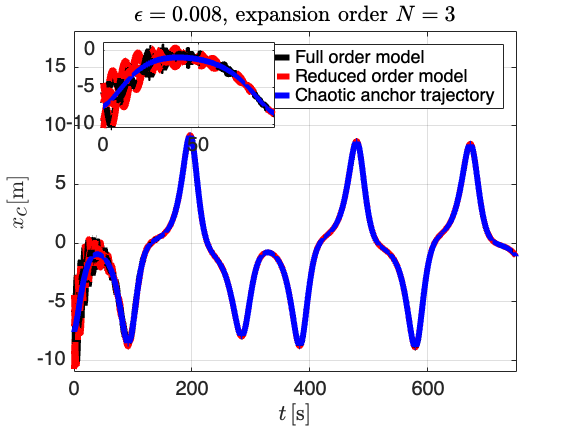

Elapsed time is 35.440020 seconds.


Elapsed time is 0.111843 seconds.


Elapsed time is 26.322121 seconds.


Elapsed time is 0.115498 seconds.


Elapsed time is 27.890856 seconds.


Elapsed time is 0.096051 seconds.


Elapsed time is 27.417716 seconds.


Elapsed time is 0.093510 seconds.


Elapsed time is 25.658785 seconds.


Elapsed time is 0.082130 seconds.


Elapsed time is 24.871938 seconds.


Elapsed time is 0.078840 seconds.


fontsize(fig, 20, "points")
set(gcf,'color','w');
box on
grid on ;
axis([0,750,-11,18])
ax1 = gca;
ax2 = axes( 'Position' ,[.18 .7 .3 .2]);
box on
grid on ;
NMTET = [];
zo = [1.5*exp(-1i*pi/2),1.5*exp(1i*pi/2),2.5*exp(-1i*pi/2),2.5*exp(1i*pi/2),1*exp(1i*0.5),1*exp(-1i*0.5)];
for ind = 1:6
epsilon = 0.008;
ctspan = linspace(0,6,4000)/epsilon;
ROM=@(t,z) rom_temp_model_adiabatic(t,z,SSM_Coeff_A_2,SSM_Coeff_A_1,xi_01,xi_11,xi_21,Valpha,ValphaD,V,A,Force_Lorenz,Dalpha,gamma,epsilon);
q0 = zo(ind);
[y0,model0,Net_Sol0] = compute_SSM_phy(XI_0,XI_1,XI_2,XI_3,ctspan(1),gamma,q0,epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

IC = [real(q0);imag(q0)];

tic 
[t_sol,ROM_sol] = ode45(ROM,ctspan,IC);
toc

[y,modal,Net_Sol] = compute_SSM_phy(XI_0,XI_1,XI_2,XI_3,t_sol,gamma,(ROM_sol(:,1)+1i*ROM_sol(:,2)).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);


FullS = @(t,y) full_system(t,y,epsilon,Force_Lorenz);
tic
IC =y0;
[tSP,SP_Traj] = ode45(FullS,ctspan,IC);
toc
% % save('OrderOmega0.1.mat','SP_Traj','y','Net_Sol','tSP');
% 
yT = SP_Traj.';
F_auto = A*[yT(1,:);yT(2,:);yT(3,:);yT(4,:);yT(5,:);yT(6,:)] + [0*yT(1,:);0*yT(1,:);0*yT(1,:);-gamma*(m1+Mf)/(m1*Mf)*yT(1,:).^3;gamma/m1*yT(1,:).^3;(Force_Lorenz(tSP*epsilon)/(m1+m2+Mf)).'];
F_net_1 = sqrt(sum(F_auto.^2));
F_net = [F_net;F_net_1];
 hold(ax1, 'on' );
indexR = 3;
plot(ax1,tSP,SP_Traj(:,indexR),'-','LineWidth',3,'color','black')
hold on 
plot(ax1,tSP,y(indexR,:),'--','LineWidth',3,'color','red')
hold on 
plot(ax1,tSP,Net_Sol(indexR,:),'-','LineWidth',3,'color',[0 0 1 0.3])
hold on 
xlabel(ax1,'$t \,[$s$]$','Interpreter','latex');
ylabel(ax1,'$x_c \,[$m$]$','Interpreter','latex');
legend(ax1,'Full order model','Reduced order model','Chaotic anchor trajectory')
title(ax1,'$\epsilon = 0.008$, expansion order $N=3$','Interpreter','latex')
hold on

grid on ;

% ax2 = axes( 'Position' ,[.2 .7 .5 .2])
hold(ax2, 'on' );
hold on 
plot(ax2,tSP,SP_Traj(:,indexR),'-','LineWidth',3,'color','black')
hold on 
plot(ax2,tSP,y(indexR,:),'--','LineWidth',3,'color','red')
hold on 
plot(ax2,tSP,Net_Sol(indexR,:),'-','LineWidth',3,'color',[0 0 1 0.3])
hold on 
% xlabel(ax2,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax2,'$x_{c} \,[$m$]$','Interpreter','latex');
axis([0,90,-10.5,1])
grid on ;

NMTE = sum(sqrt(sum((y.' - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
NMTET = [NMTET,NMTE];
end

% origUnits = fig.Units;
% fig.Units = fig.PaperUnits;
% fig.PaperSize = fig.Position(3:4);
% fig.Units = origUnits;
% exportgraphics(fig, 'e008xcdot_slow.pdf');

NMTEavg = sum(NMTET)/6;


SSM snapshot

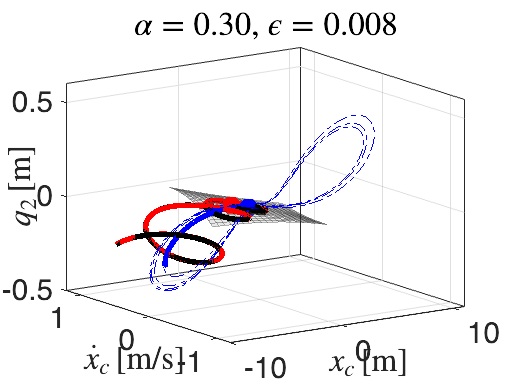

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [20×20 double]
           YData: [20×20 double]
           ZData: [20×20 double]
           CData: [20×20 double]

  Show all properties


hFig = figure('DefaultAxesFontSize',18);                       % Bring up new figure
% imshow('board.tif','Border','tight') % The axes will fill up the entire figure as much as possible without changing aspect ratio.
% hFig.WindowState = 'maximized';
% pause(0.5)
delta = 0.5;
tl =  200-1;
% tl = 1000;
clear movieVector
shift_traj = y;
% shift_trajZ = [real(modal(1,:));imag(modal(1,:));imag(modal(4,:));real(modal(4,:))];%y;
% ind = 1;
% SP_TrajZ = inv(V)*SP_Traj.';
% SP_TrajZ = [real(SP_TrajZ(1,:));imag(SP_TrajZ(1,:));imag(SP_TrajZ(4,:));real(SP_TrajZ(4,:))];
% SolutionZ = inv(V)*SolutionA.';
% SolutionZ = [real(SolutionZ(1,:));imag(SolutionZ(1,:));imag(SolutionZ(4,:));real(SolutionZ(4,:))];
% 
% Solution1 = SolutionA.';
SP_Traj1 = SP_Traj.';

ind = 1;
SolutionA = Net_Sol;
nssm = 20;
for j = 1:1 %1:1:2500 %200:200%3500:3500 %1:1 %1:1:2500 %1:1 %3500:3500 %500:500 %1:20:10000-tl % 1:100:70000%:1200%(max(size(t_sol))-tl)
i = 1+0;
     clf
% subplot(2, 2, [1 3])
     rhosamp = linspace(0,0.5,201);
     plotdofs = [3 6 2]; 
     [RHO,Theta]=meshgrid(linspace(0,2,nssm),linspace(0,2*pi,nssm));
     Z = RHO.*exp(1i*Theta);
     x = linspace(-1,1,nssm);
     [X,Y]=meshgrid(x);
     Z = RHO.*exp(1i*Theta);
     Z = X+1i*Y;
     t_ssm = ones(1,nssm*nssm)*tSP(j+tl);
[ZZ,modalZ,Net_Solz] = compute_SSM_phy(XI_0,XI_1,XI_2,XI_3,t_ssm,gamma,Z(:).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

     Z1 = reshape(ZZ(plotdofs(1),:),nssm,nssm);
     Z2 = reshape(ZZ(plotdofs(2),:),nssm,nssm);
     Z3 = reshape(ZZ(plotdofs(3),:),nssm,nssm);


     h = surf(Z1,Z2,Z3)
     h.EdgeColor = [0 0 0];
     h.FaceColor = [.7 .7 .7];
     h.FaceAlpha = 0.3;
     h.EdgeAlpha = 0.3;
     hold on 

     starto = 1;
     

     plot3(SolutionA(plotdofs(1),1:1:end),SolutionA(plotdofs(2),1:1:end),SolutionA(plotdofs(3),1:1:end),'-.','color',[0,0,1,0.8])
     hold on
     flm = plot3(SP_Traj1(plotdofs(1),j:j+tl),SP_Traj1(plotdofs(2),j:j+tl),SP_Traj1(plotdofs(3),j:j+tl),'-','LineWidth',3,'Color',[0 0 0 0.5]);
     hold on
     roml = plot3(shift_traj(plotdofs(1),j:j+tl),shift_traj(plotdofs(2),j:j+tl),shift_traj(plotdofs(3),j:j+tl),'-','LineWidth',3,'Color',[1 0 0 0.5]);
     hold on
     anl = plot3(SolutionA(plotdofs(1),j:j+tl),SolutionA(plotdofs(2),j:j+tl),SolutionA(plotdofs(3),j:j+tl),'-','LineWidth',3,'color',[0,0,1,0.8]);
     hold on
     plot3(shift_traj(plotdofs(1),j+tl),shift_traj(plotdofs(2),j+tl),shift_traj(plotdofs(3),j+tl),'.','MarkerSize',30,'Color','red');
     hold on
     plot3(SP_Traj1(plotdofs(1),j+tl),SP_Traj1(plotdofs(2),j+tl),SP_Traj1(plotdofs(3),j+tl),'.','MarkerSize',30,'Color','black');
     hold on
     plot3(SolutionA(plotdofs(1),j+tl),SolutionA(plotdofs(2),j+tl),SolutionA(plotdofs(3),j+tl),'.','MarkerSize',30,'Color',[0,0,1]);
     hold on
      
    xl = xlabel('$x_c \,[$m$]$','Interpreter','latex');
    xl.Position = [12.5945 0.4649 -0.8820];
    xl.HorizontalAlignment = 'center';
    xticks([-10 0 10])
    yl = ylabel('$\dot{x}_c \,[$m/s$]$','Interpreter','latex');
    yl.Position = [-6.0494 0.8585 -0.7246];
    yticks([-1 0 1])
     zl = zlabel('$q_2 \,[$m$]$','Interpreter','latex');
     zl.Position = [-11.3834 1.3175 0.0584];
     zticks([-0.5 0 0.5])
%        title('Adiabatic SSM reduction, $\epsilon = 0.008$','Interpreter','latex')
%          legend('SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','$O(\epsilon^3)$ anchor trajectory','Full order model','Reduced order model','$O(\epsilon^3)$ anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','Interpreter','latex','location','northwest')
%      lk =  legend([h flm roml anl],'SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','Full order model','Reduced order model','Chaotic anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','Interpreter','latex','location','northwest')
%  lk.Position = [0.1559 0.7391 0.5865 0.1986];
    string = strcat('$\alpha = $',num2str(round(epsilon*t_sol(j+tl),2),'%4.2f' ),', $\epsilon = 0.008$');
    if (round(epsilon*t_sol(j+tl),2)) >=8
     string = strcat('{\color{blue}\alpha = ',num2str(round(epsilon*t_sol(j+tl),2),'%4.2f' ),',}\epsilon = 0.008');
     title(string,'Interpreter','latex');
    else
     title(string,'Interpreter','latex');
    end   
   axis([-10,11,-1.2,1.2,-0.5,0.6])
   view(-35,17)
    grid on
    box on
%            daspect([1,1,1])
%  axis([-0.2,0.2,-0.2,0.2,-0.01,0.01])
set(gcf,'color','white')
    figssm = gcf;
set(hFig, 'Units' , 'Inches' );
pos = get(hFig, 'Position' );
set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
set(gcf,'Renderer','painters')

movieVector(ind) = getframe(hFig);
    
    ind = ind +1;

end


% myWriter = VideoWriter('SSM_Shaking_Cart_adiabatic','MPEG-4');
% % myWriter.FrameRate = 40;
% % 
% % open(myWriter);
% % writeVideo(myWriter,movieVector);
% % close(myWriter);
% 
% myWriter.FrameRate = 80;
% 
% open(myWriter);
% 
% for indj = 1:2500
% writeVideo(myWriter,movieVector(indj));
% end
% 
% close(myWriter);

% set(hFig, 'Units' , 'Inches' );
% pos = get(hFig, 'Position' );
% set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(hFig, 'ssm_shaking_cart_slow_snap2.pdf' , '-dpdf')

Computing the non-dimensional foricng speed. 

m1 = 1;
m2 = 1;
Mf = 2;
kf = 1;
k = 1;
c = 0.3;
cf = 0.3;
gamma = 0.5;
MTT = m1 + m2 + Mf;
K = [-2*k - kf*((m1 + m2)/MTT)^2, -k - kf*m2*(m1 + m2)/MTT^2, kf*(m1+m2)/MTT; -k - kf*m2*(m1 + m2)/MTT^2, -2*k - kf*m2^2/(MTT^2), kf*m2/MTT; (m1 + m2)/MTT *kf, m2/MTT*kf, -kf];
C = [-c - cf*((m1 + m2)/MTT)^2, -c - cf*m2*(m1 + m2)/MTT^2, cf*(m1+m2)/MTT; -c - cf*m2*(m1 + m2)/MTT^2, -2*c - cf*m2^2/(MTT^2), cf*m2/MTT; (m1 + m2)/MTT *cf, m2/MTT*cf, -cf];
M =  [Mf*(m1 + m2)/MTT, m2*Mf/MTT, 0; m2*Mf/MTT, m2*(m1 + Mf)/MTT, 0; 0,0, MTT];


A = [zeros(3),eye(3);inv(M)*K,inv(M)*C];

F_I_net = [];

NMTET = [];
nssm = 30;
x = linspace(-1,1,nssm);
[X,Y]=meshgrid(x);
Z = X+1i*Y;
Net1 = zeros(nssm,nssm);
Net2 = zeros(nssm,nssm);

Ratio_Net = zeros(nssm,nssm);
for ind = 1:nssm
    for indk = 1:nssm
    epsilon = 0.01; % Fixed time window.
    ctspan = linspace(0,6,4000)/epsilon;
    ROM=@(t,z) rom_temp_model_adiabatic(t,z,SSM_Coeff_A_2,SSM_Coeff_A_1,xi_01,xi_11,xi_21,Valpha,V,A,Force_Lorenz,Dalpha,gamma,epsilon);
    q0 = Z(ind,indk);
    [y0,model0,Net_Sol0] = compute_SSM_phy(XI_0,XI_1,XI_2,XI_3,ctspan(1),gamma,q0,epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

    IC = [real(q0);imag(q0)];


    FullS = @(t,y) full_system(t,y,0,Force_Lorenz);
    tic
    IC =y0;
    [tSP,SP_Traj] = ode45(FullS,ctspan,IC);
    toc
    yT = SP_Traj.';

    epsilon = 0.008; 
    F_an = (abs(Force_Lorenz(epsilon*tSP))).';
    % F_an = trapz(tSP,F_an)/(max(tSP)*mean(F_an));
    F_spring = K*[yT(1,:);yT(2,:);yT(3,:)];
    F_damper = C*[yT(4,:);yT(5,:);yT(6,:)];
    F_nonlinear = [gamma*yT(1,:).^3;0*yT(1,:);0*yT(1,:)];
    F_total = F_spring + F_damper + F_nonlinear;
    F_net = sqrt(sum(F_total.^2));

    [dXdF_net, Xtrunc_net,tSp_red] = ftd(F_net, tSP.');
    [dXdF_an, Xtrunc_an,tSp_red] = ftd(F_an, tSP.');
    F_I_net = [F_I_net;trapz(tSP,F_an./F_net)/(max(tSP))];

    Net1(ind,indk) = trapz(tSp_red,abs(dXdF_an.'))/(max(tSP));
    Net2(ind,indk) = (trapz(tSp_red,abs(dXdF_net.'))/(max(tSP)));

    Ratio_Net(ind,indk) = trapz(tSp_red,abs(dXdF_an.'))/(max(tSP))./(trapz(tSp_red,abs(dXdF_net.'))/(max(tSP)));


    end
end

Elapsed time is 0.112505 seconds.
Elapsed time is 0.077656 seconds.
Elapsed time is 0.070988 seconds.
Elapsed time is 0.070403 seconds.
Elapsed time is 0.073842 seconds.
Elapsed time is 0.065578 seconds.
Elapsed time is 0.069914 seconds.
Elapsed time is 0.067010 seconds.
Elapsed time is 0.064274 seconds.
Elapsed time is 0.061466 seconds.
Elapsed time is 0.067466 seconds.
Elapsed time is 0.066205 seconds.
Elapsed time is 0.064468 seconds.
Elapsed time is 0.066628 seconds.
Elapsed time is 0.063798 seconds.
Elapsed time is 0.066696 seconds.
Elapsed time is 0.062709 seconds.
Elapsed time is 0.066283 seconds.
Elapsed time is 0.066773 seconds.
Elapsed time is 0.064220 seconds.
Elapsed time is 0.064055 seconds.
Elapsed time is 0.065265 seconds.
Elapsed time is 0.064965 seconds.
Elapsed time is 0.064050 seconds.
Elapsed time is 0.064330 seconds.
Elapsed time is 0.066019 seconds.
Elapsed time is 0.065144 seconds.
Elapsed time is 0.061589 seconds.
Elapsed time is 0.066224 seconds.
Elapsed time i


fig = figure 

fig =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


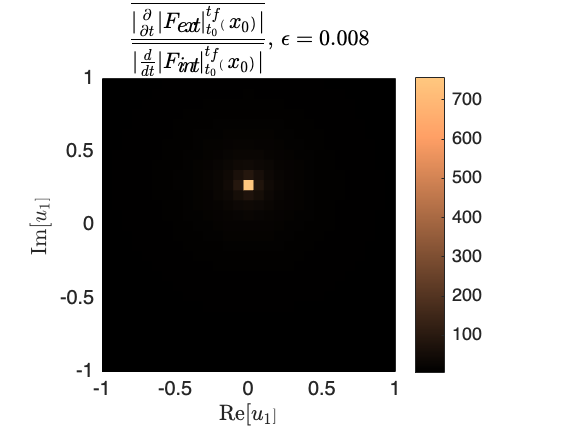

% flag = [Ratio_Net > 100];
% Ratio_Net(flag)= NaN;
bp = mean( Net1(:))./mean( Net2(:));
P = pcolor(X,Y,Ratio_Net);

% bp = mean(Ratio_Net(:));
P.EdgeColor = 'none';
colormap copper
colorbar 
xlabel('Re[$u_1$]','Interpreter','latex');
ylabel('Im[$u_1$]','Interpreter','latex');
title_string = strcat('$\displaystyle \frac{\overline{|\frac{\partial}{\partial t}|F_{ext}|_{t_0}^{t_f}(x_0)|}}{\overline{|\frac{d}{dt}|F_{int}|_{t_0}^{t_f}(x_0)|}}$, $\epsilon = ',num2str(epsilon),'$');


title(title_string,'Interpreter','latex')
daspect([1 1 1])


disp(['Forcing speed = ',num2str(bp)]);

Forcing speed = 7.2658



% set(fig, 'Units' , 'Inches' );
% pos = get(fig, 'Position' );
% set(fig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig, 'slow_small.pdf' , '-dpdf' , '-r300' )